# Diagrammi di Nyquist

s = tf('s');

## Stabilità intrinseca

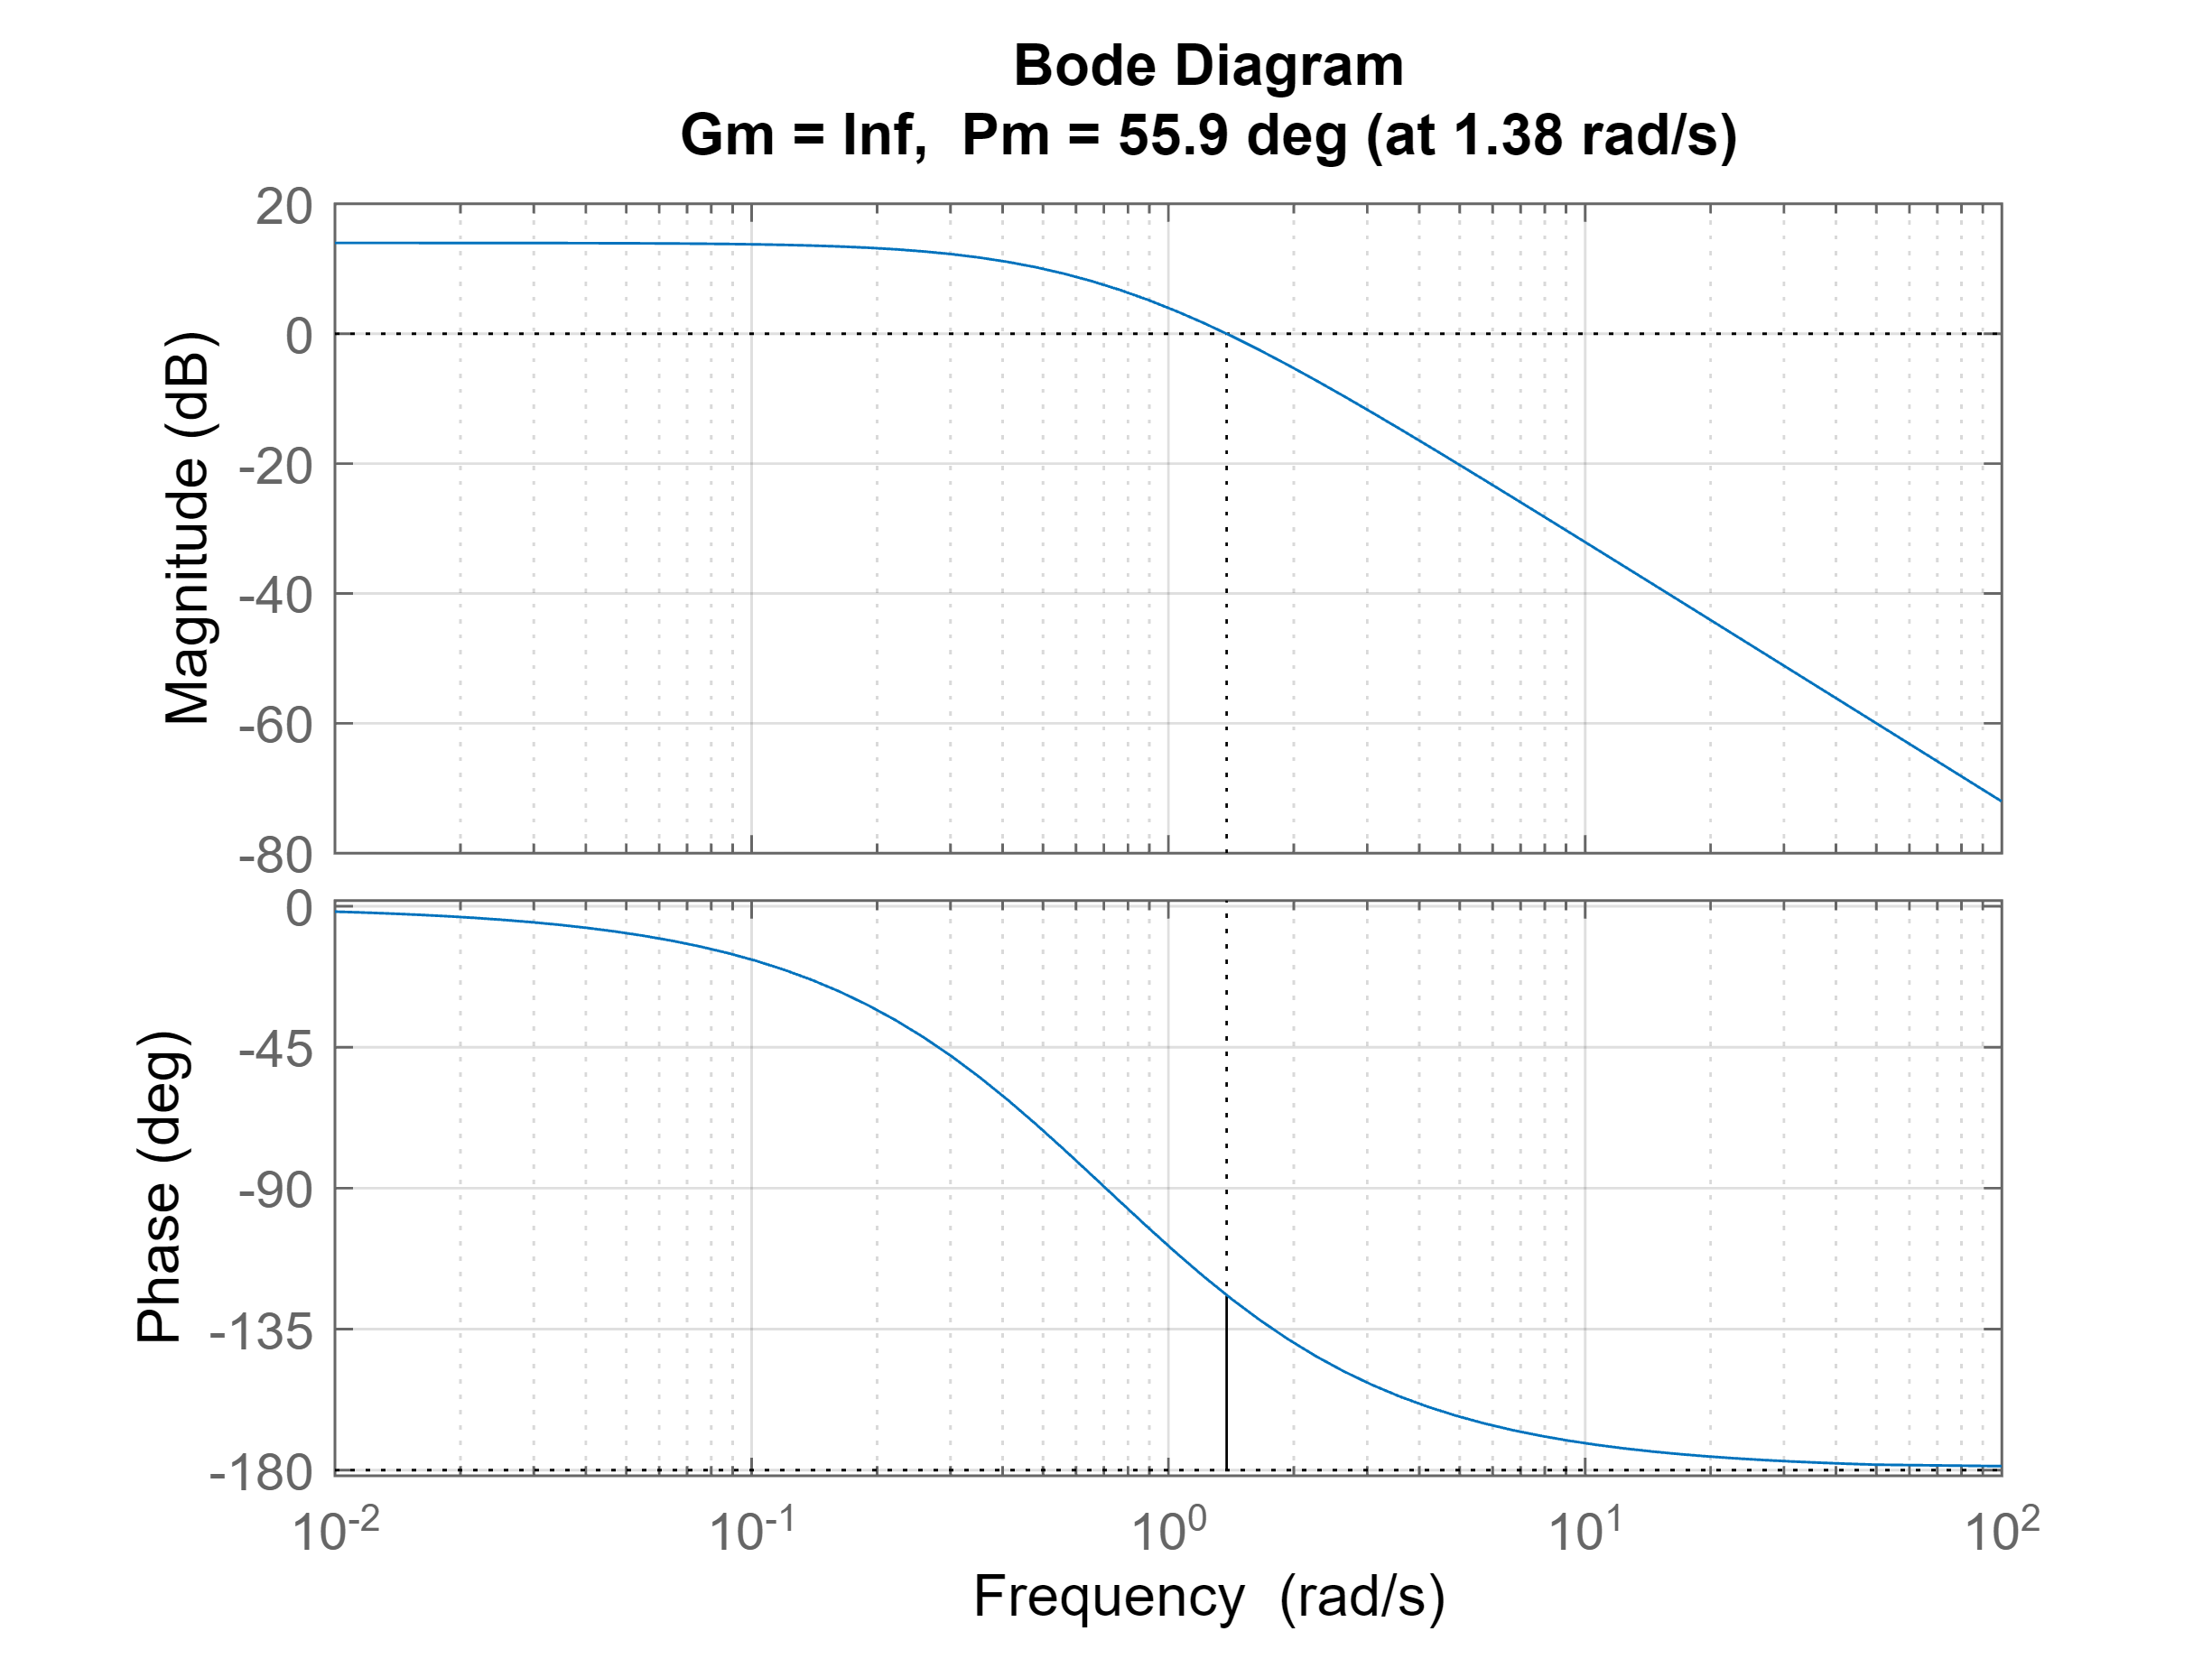

T1 = 1;
T2 = 2;
k = 5;

L = k/((1+s*T1)*(1+s*T2));

figure
margin(L), grid on

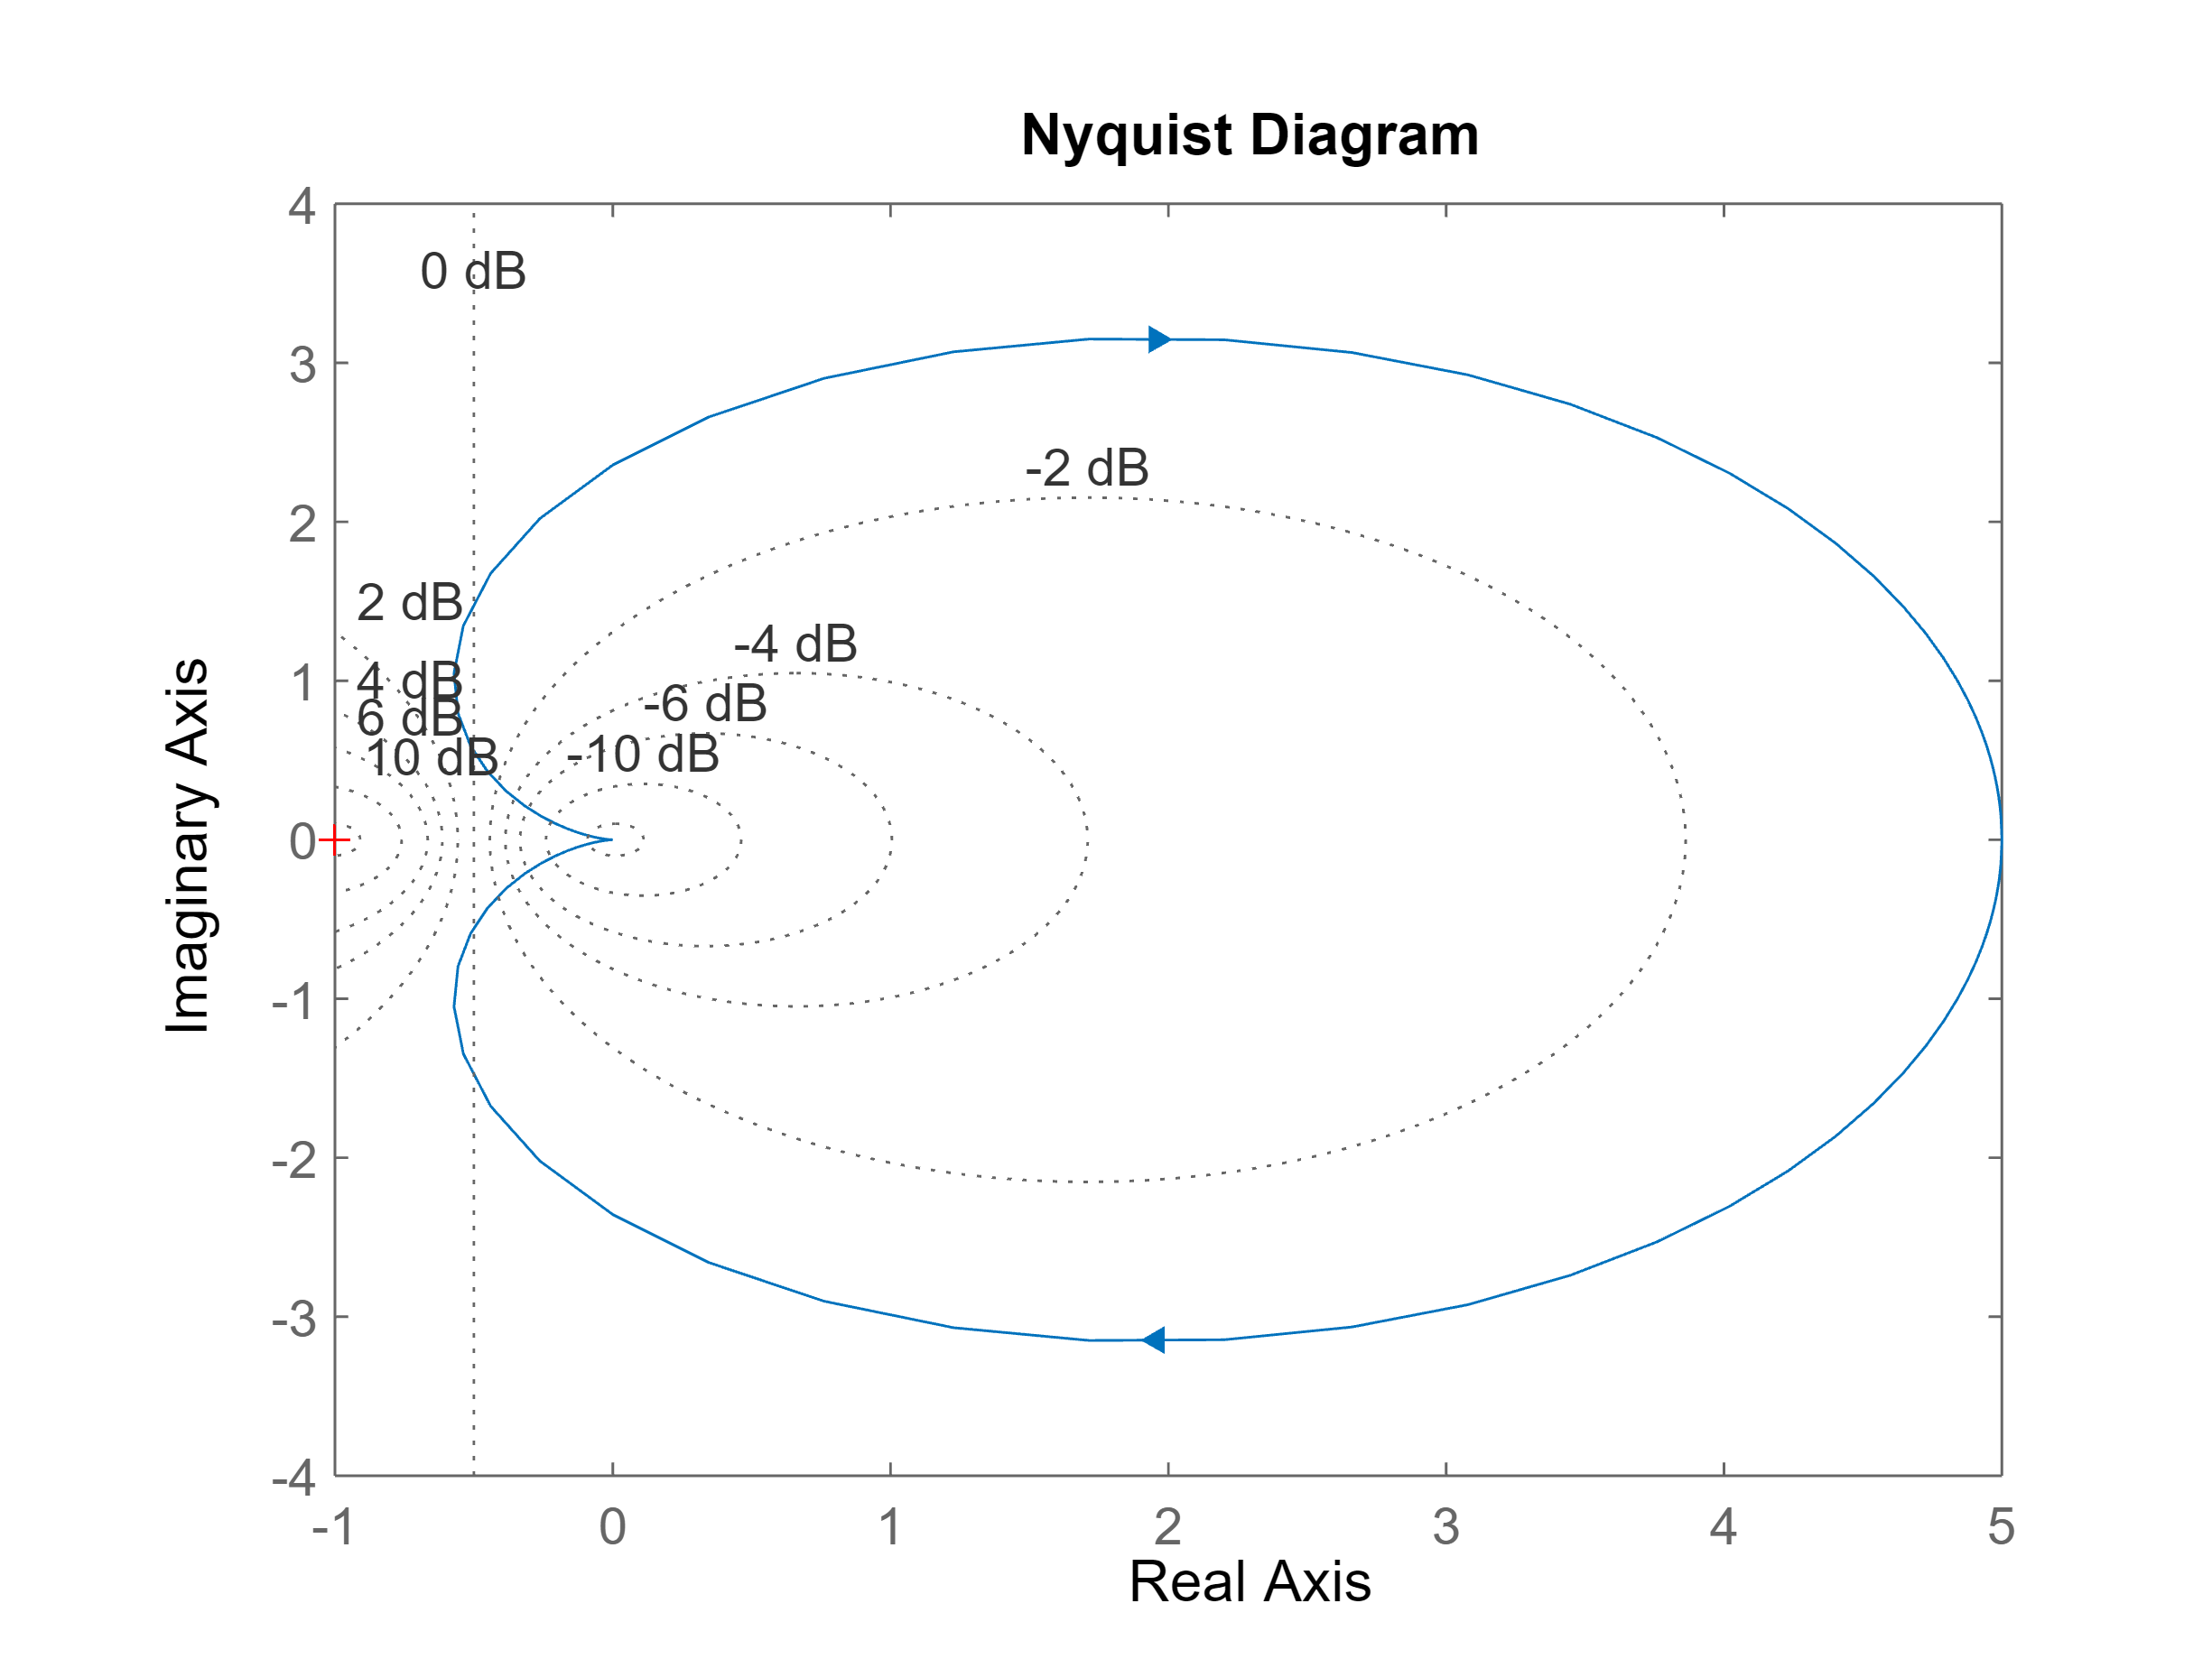

figure
nyquist(L), grid on

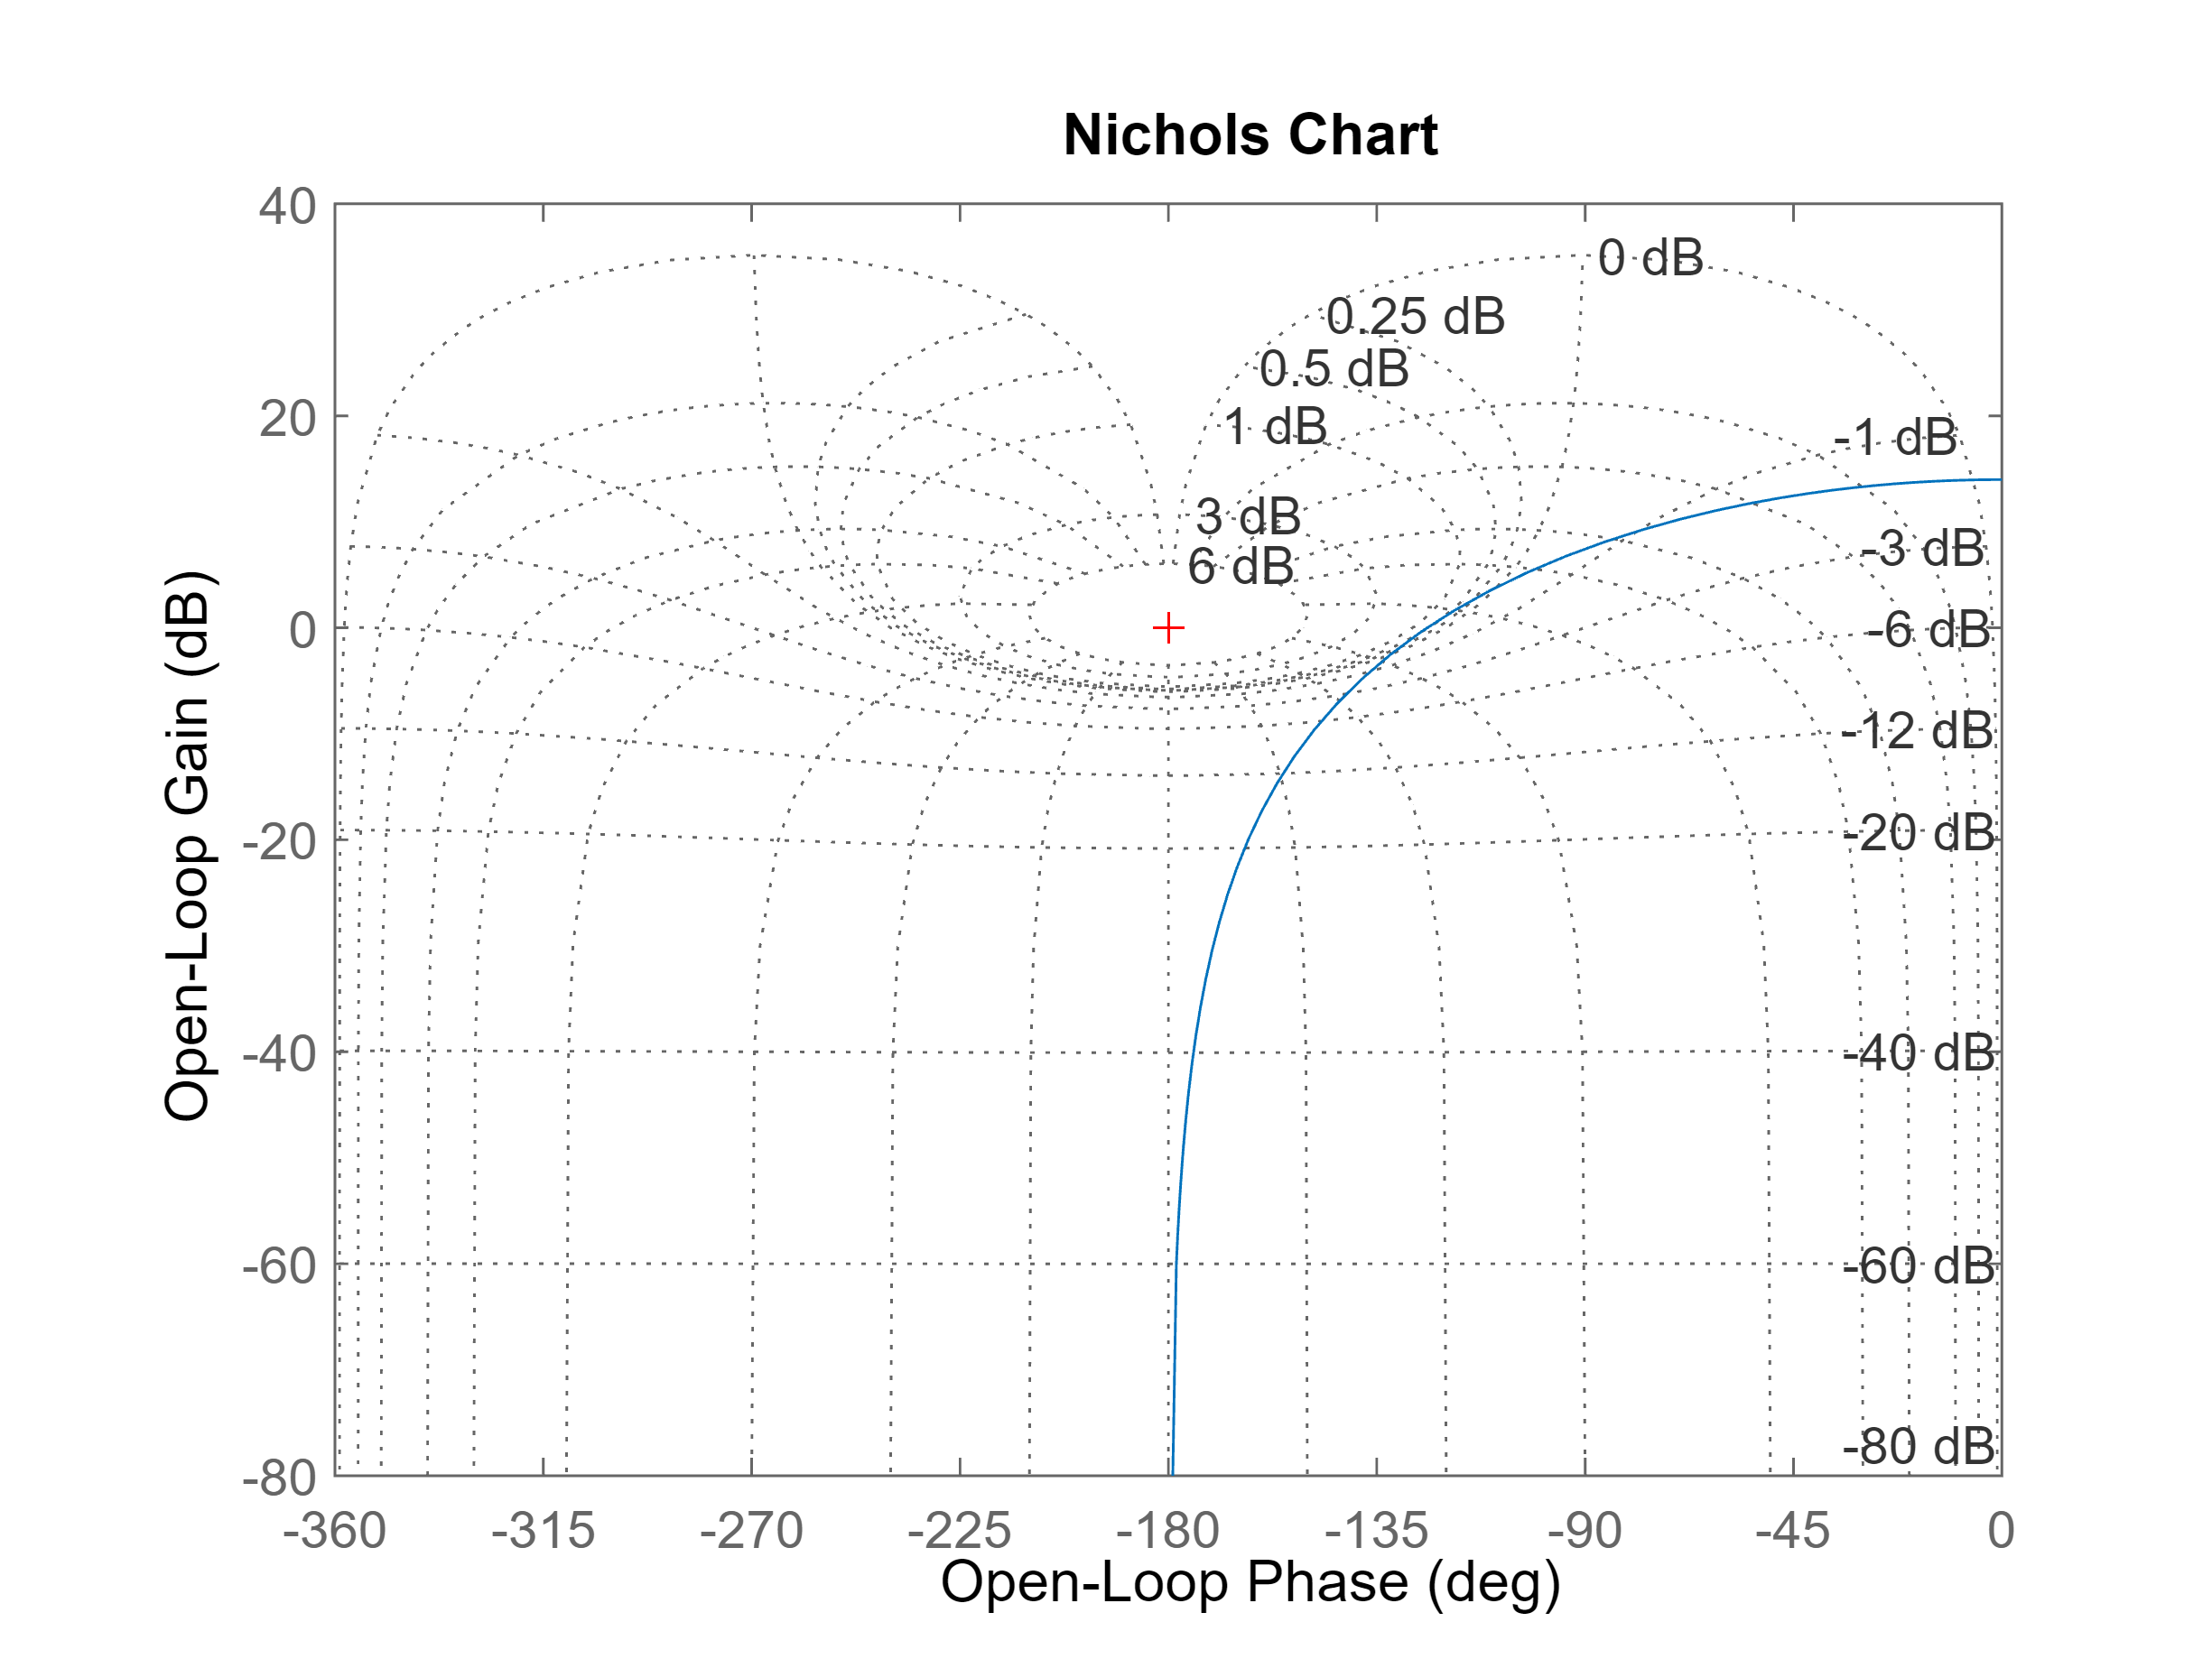

figure
nichols(L), grid on

## Stabilità regolare

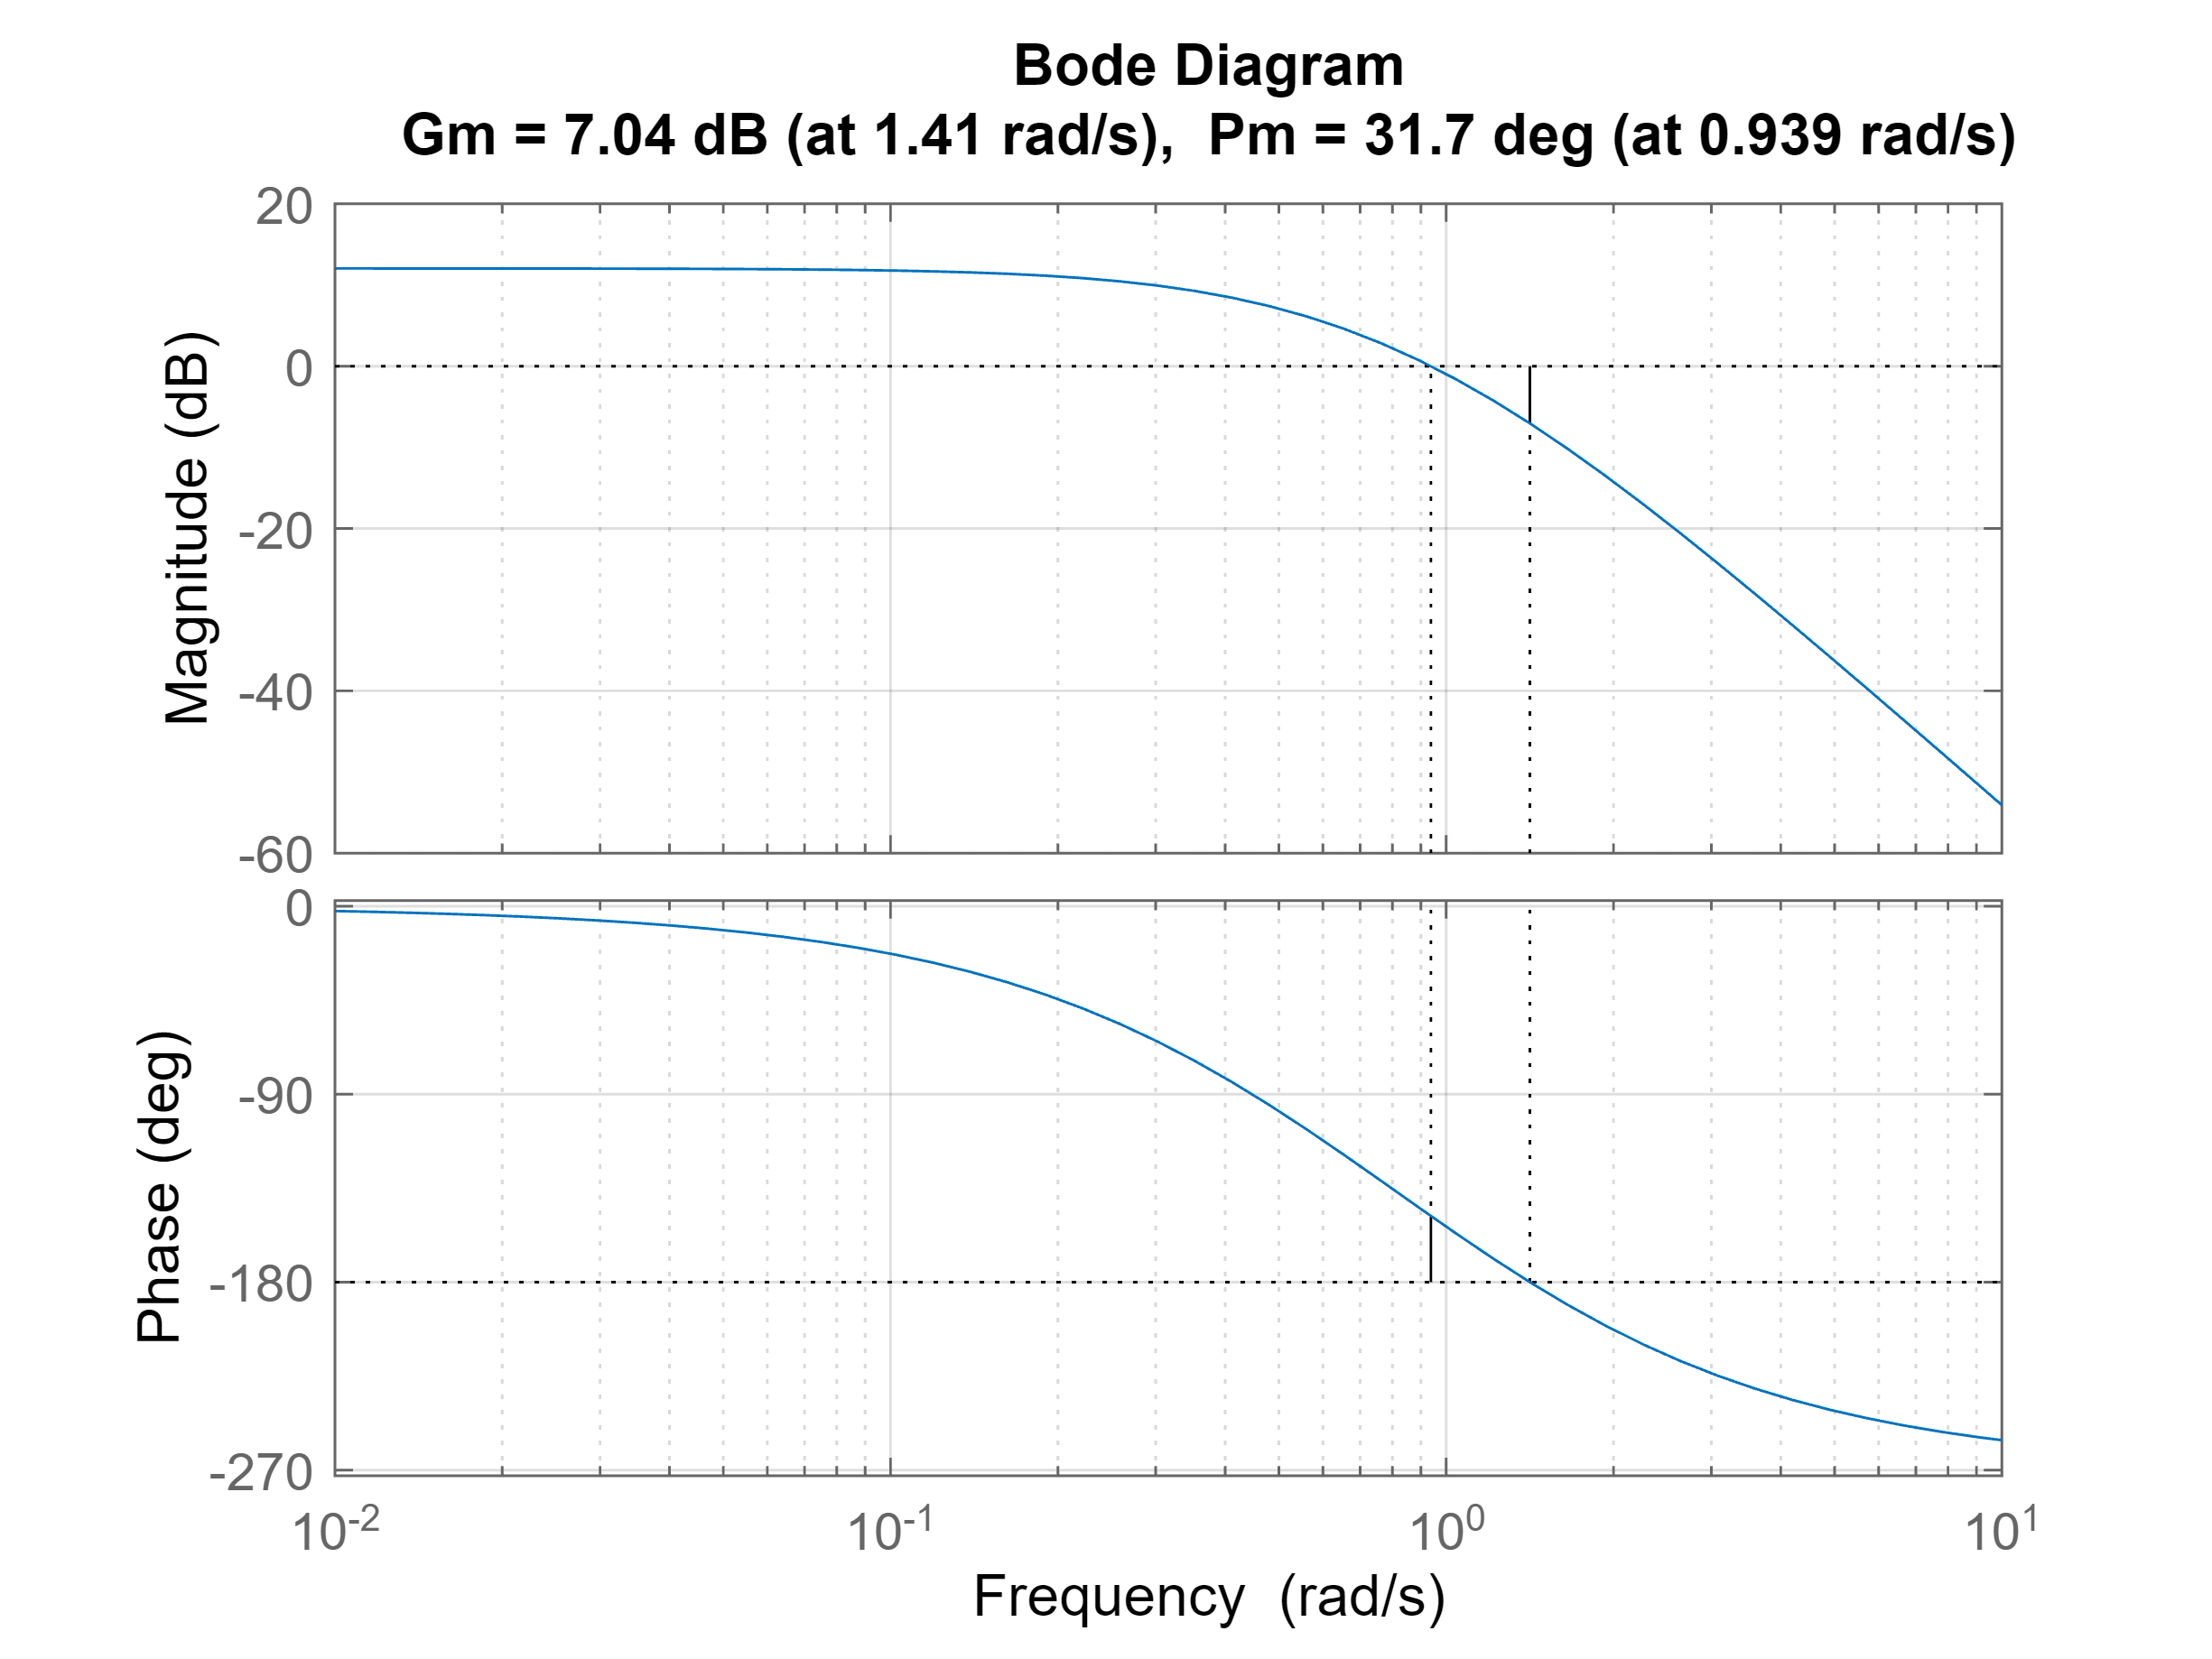

T1 = 1;
T2 = 2;
T3 = 1;
k = 4;

L = k/((1+s*T1)*(1+s*T2)*(1+s*T3));

figure
margin(L), grid on

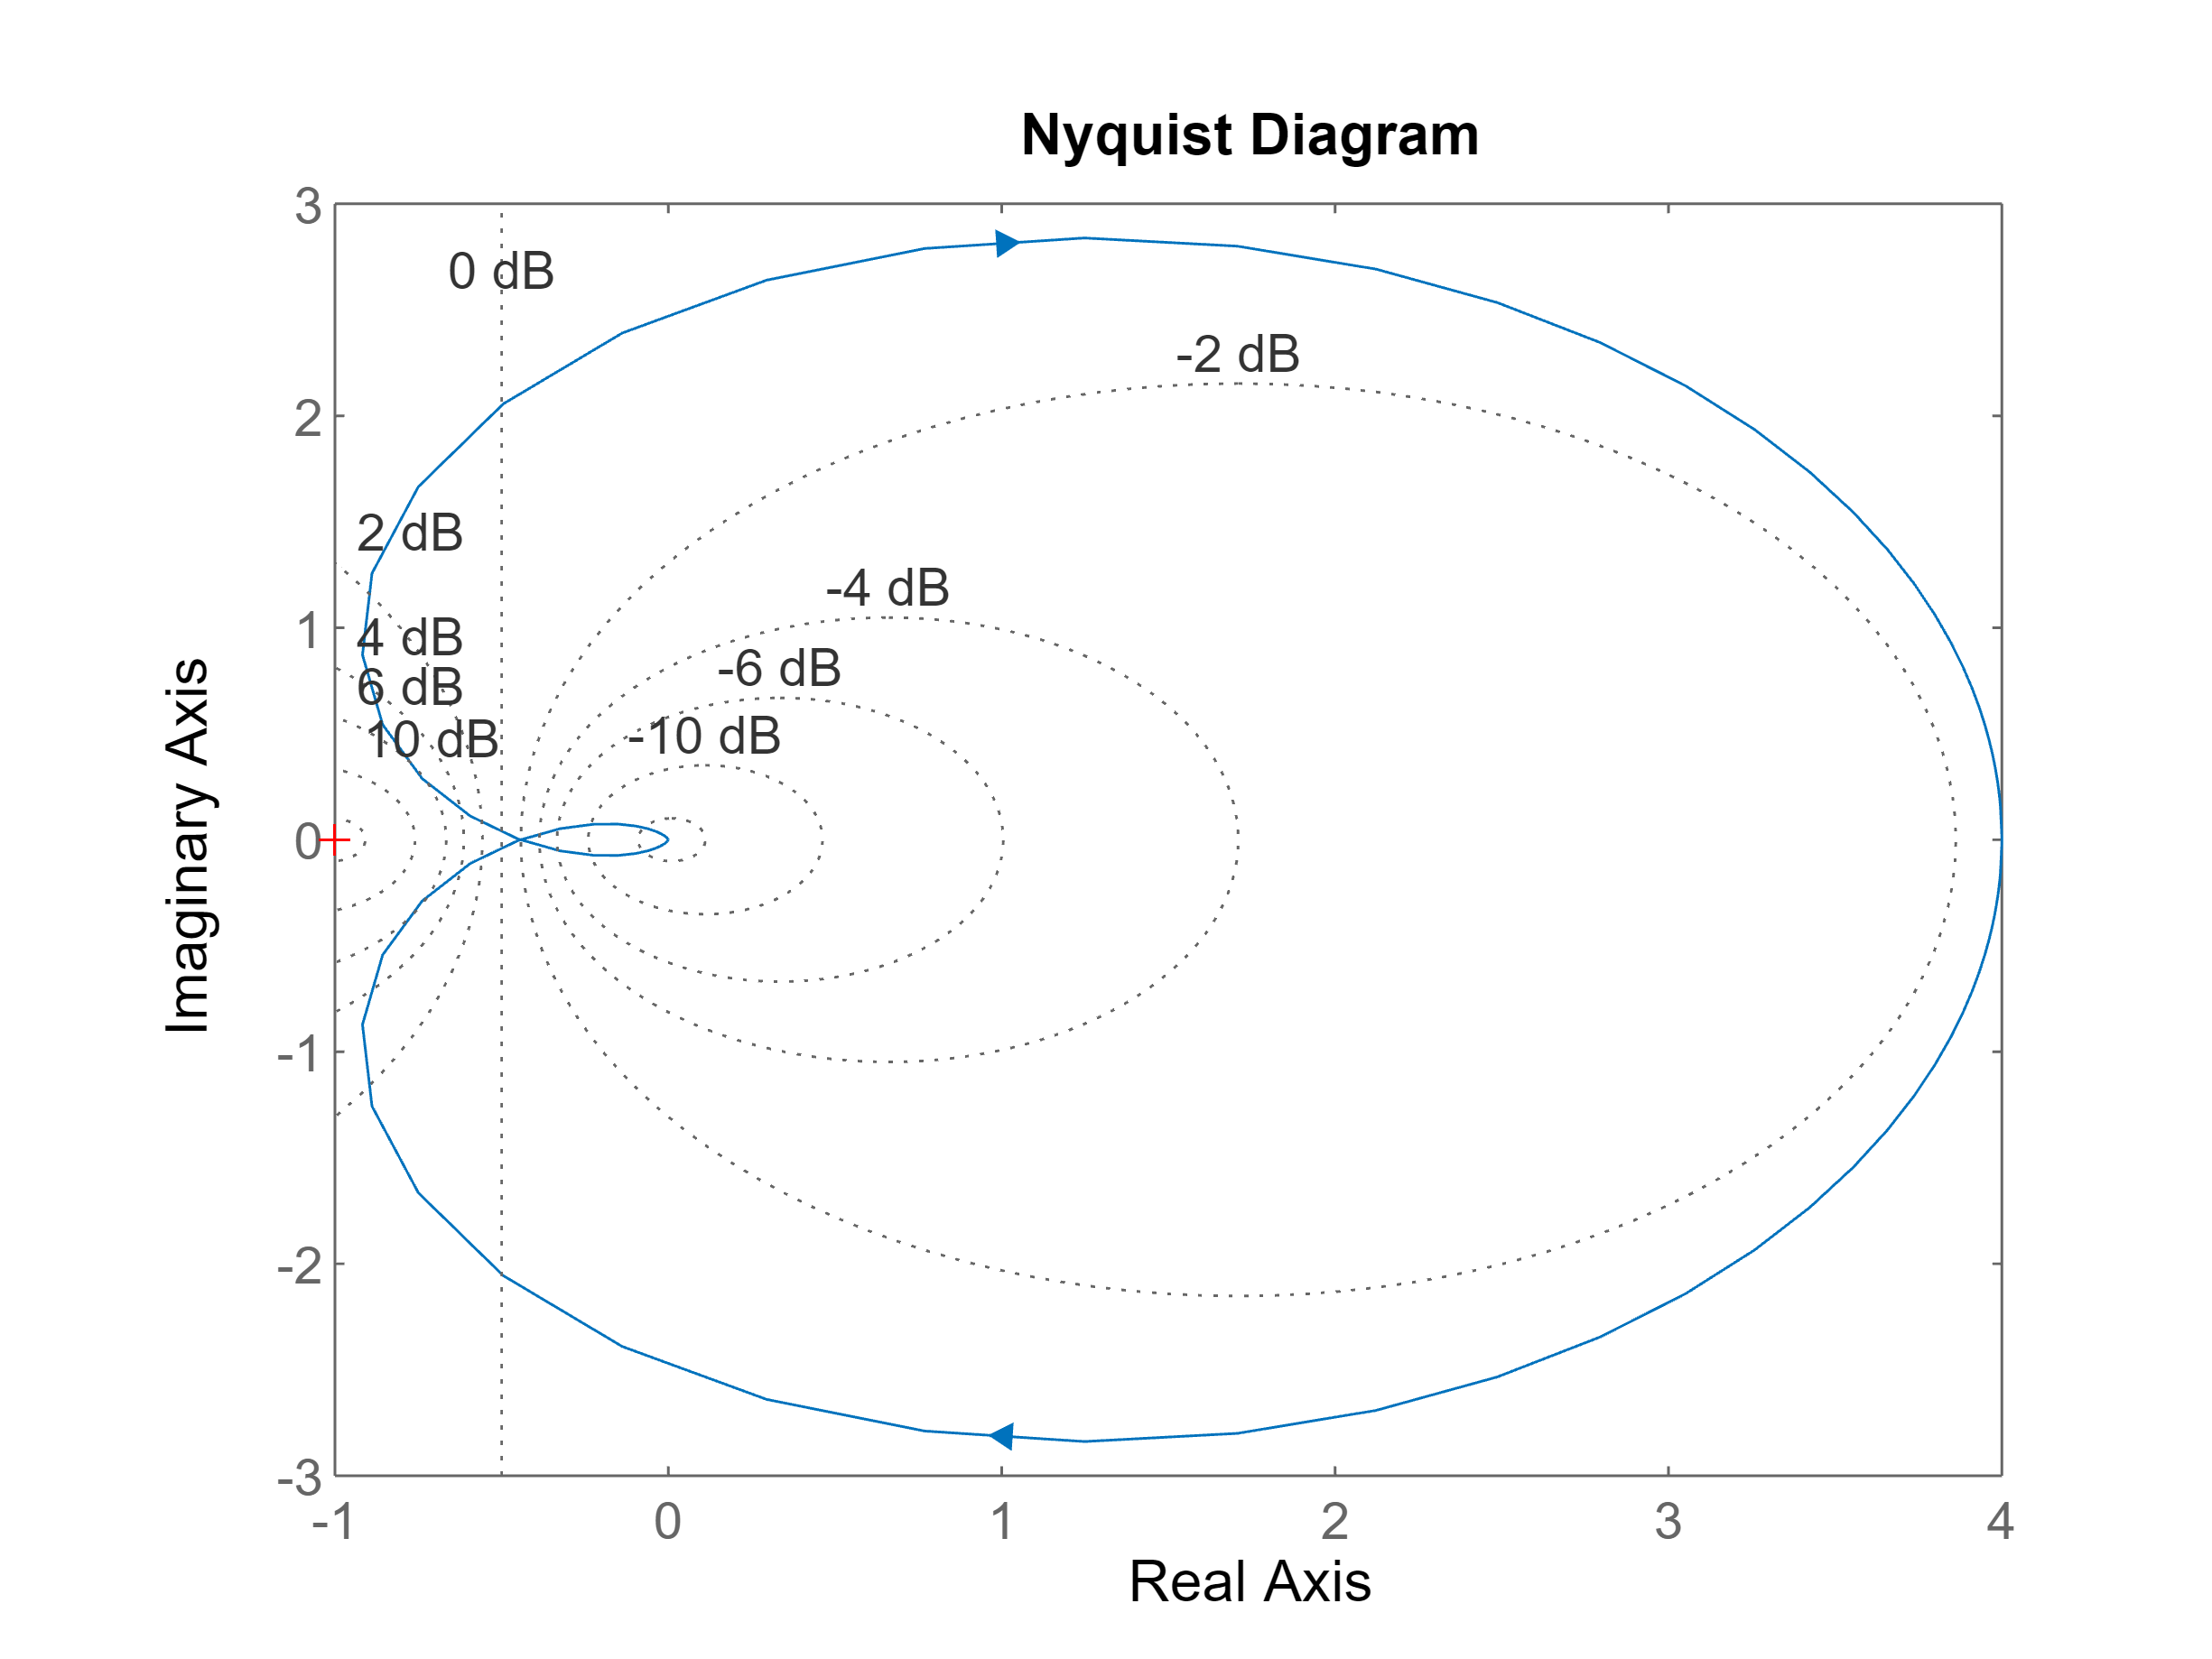

figure
nyquist(L), grid on

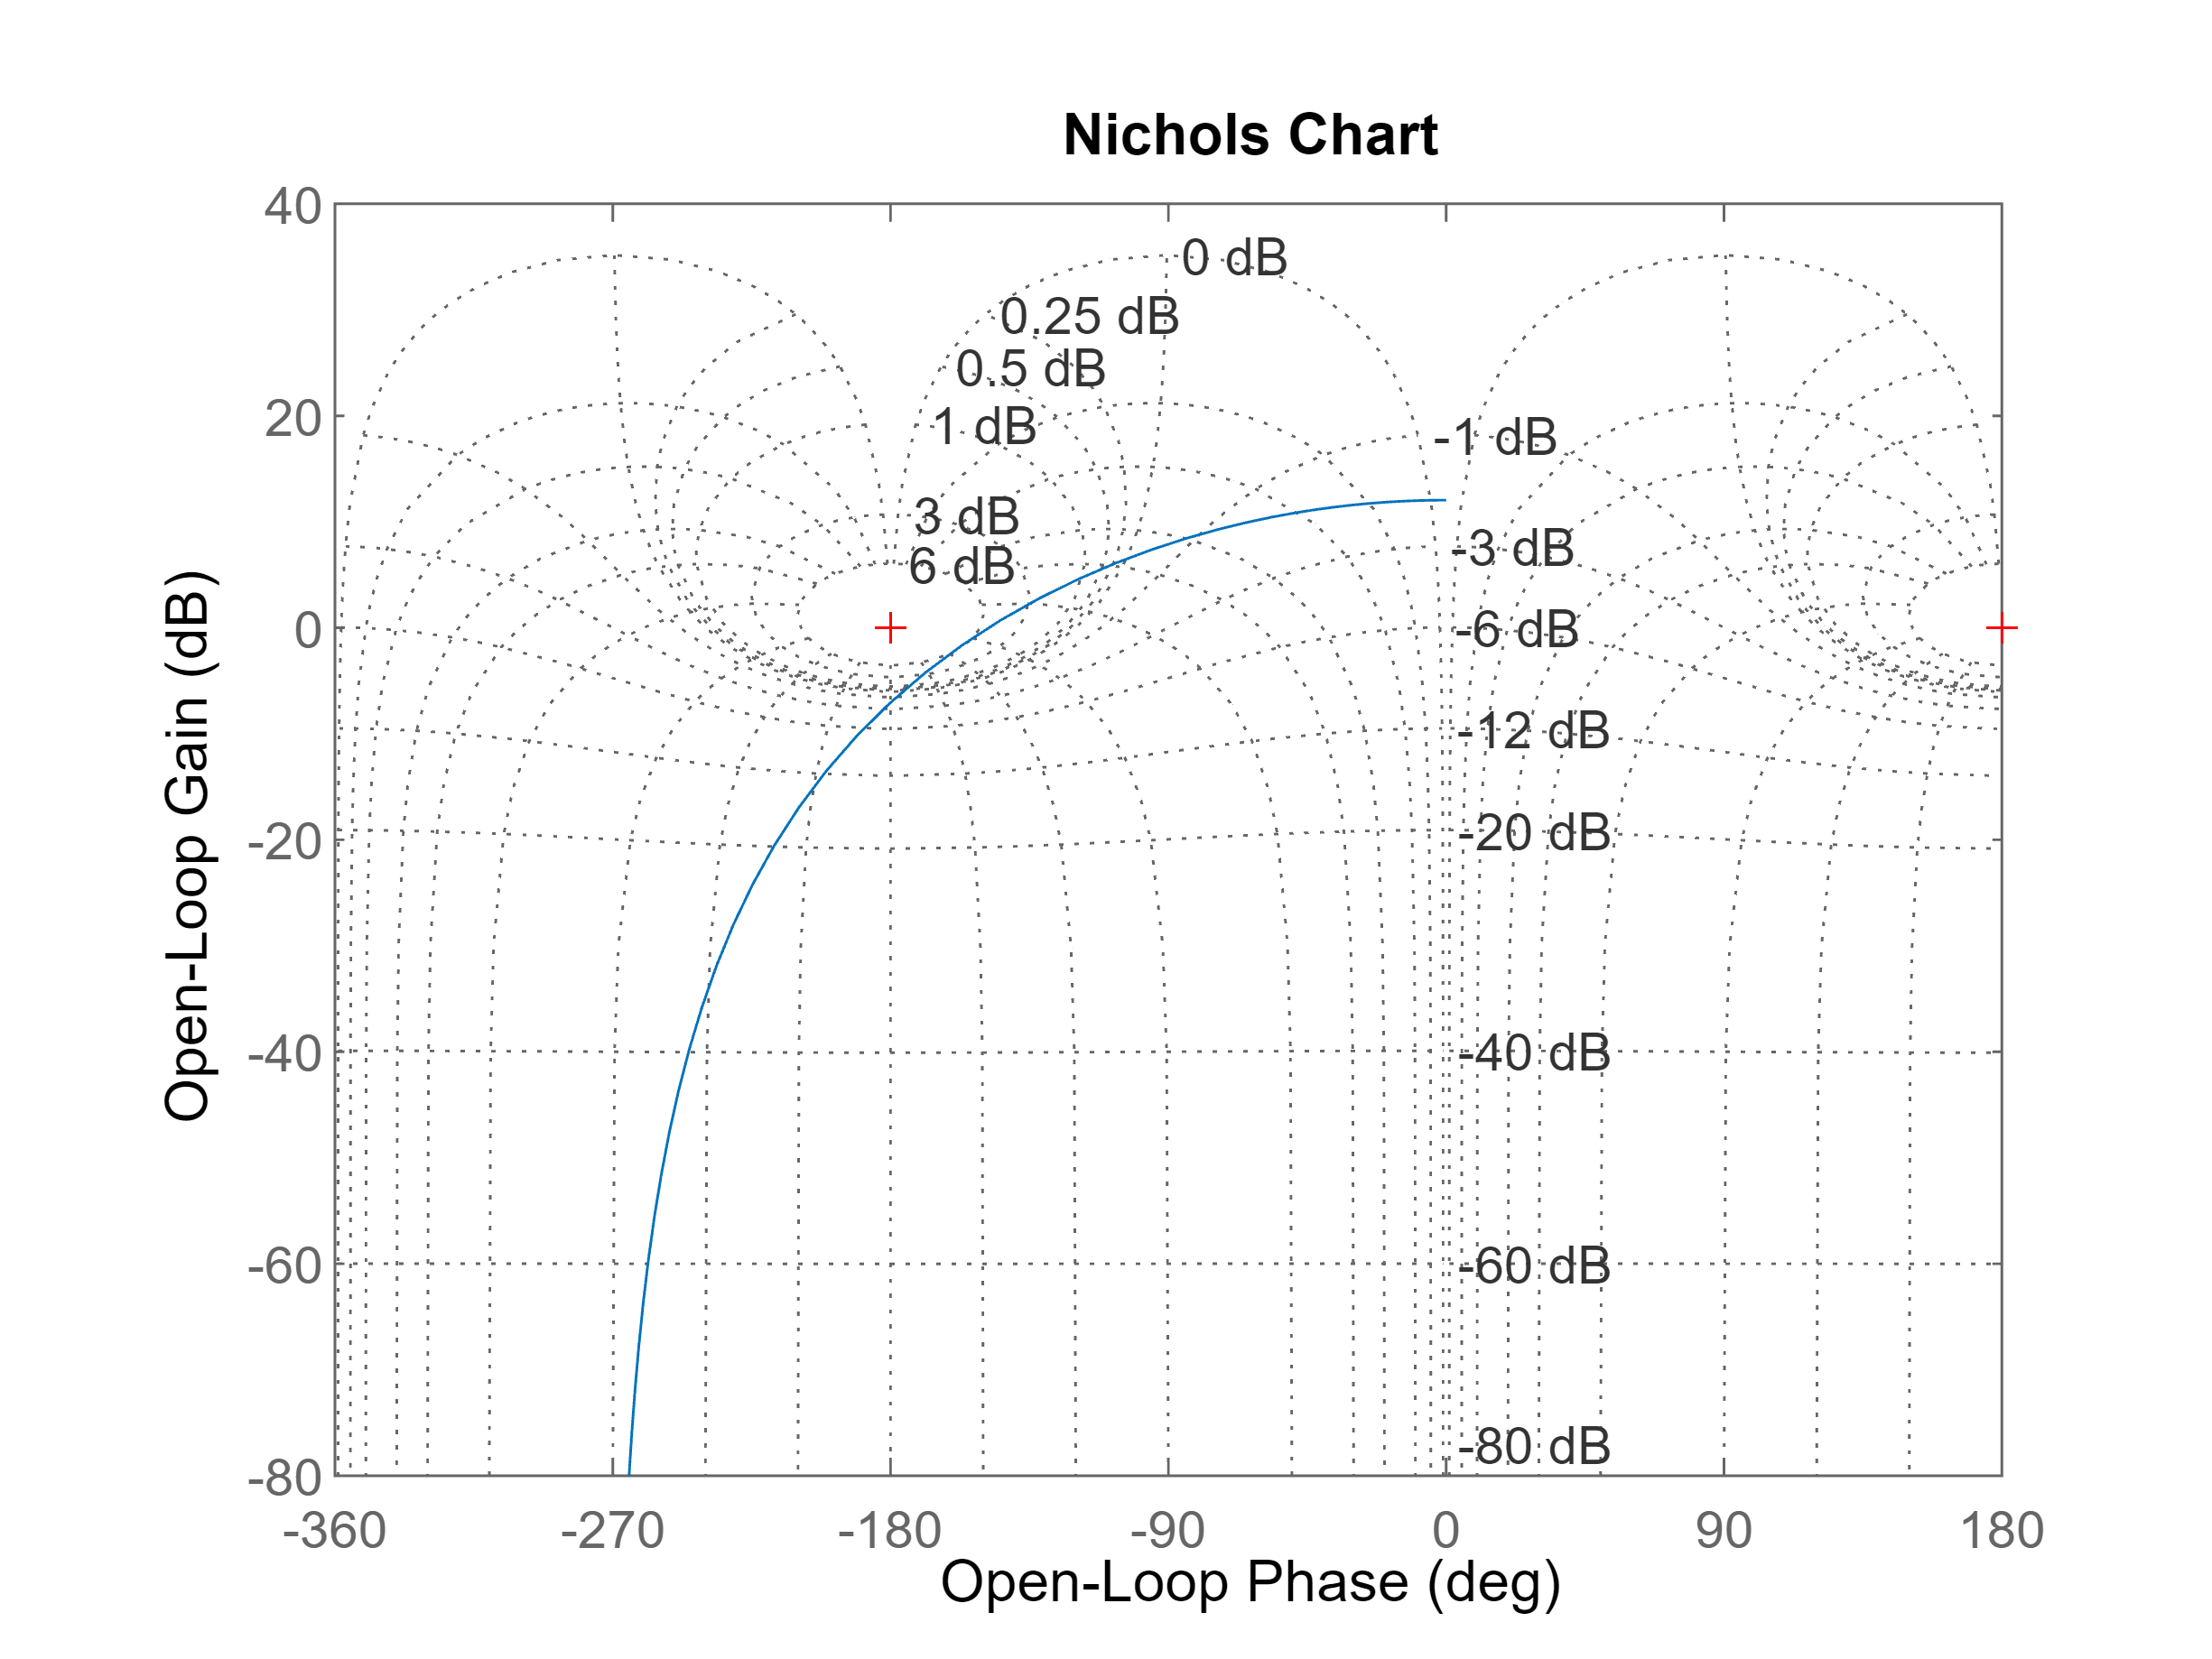

figure
nichols(L), grid on

Per questo sistema possiamo costruire un'approssimante a ciclo chiuso del secondo ordine come segue:


$$F\left(s\right)=\frac{1}{1+2\zeta \frac{s\;}{\omega_{n\;} }+\frac{s^2 }{\omega_n^{2\;} }}$$


con


$$\zeta \approx \frac{\varphi_m }{100},{\;\;\;\omega }_n \approx \omega_{c\;}$$


NOTA: il tipo di L non è sufficiente a garantire errore nullo a regime. Sappiamo già quindi che avremo un'errore alle basse frequenze approssimando la F come sopra. Possiamo tenerne conto esplicitamente inserendo un fattore 1 - 1/(1+L0) nella F approssimata.

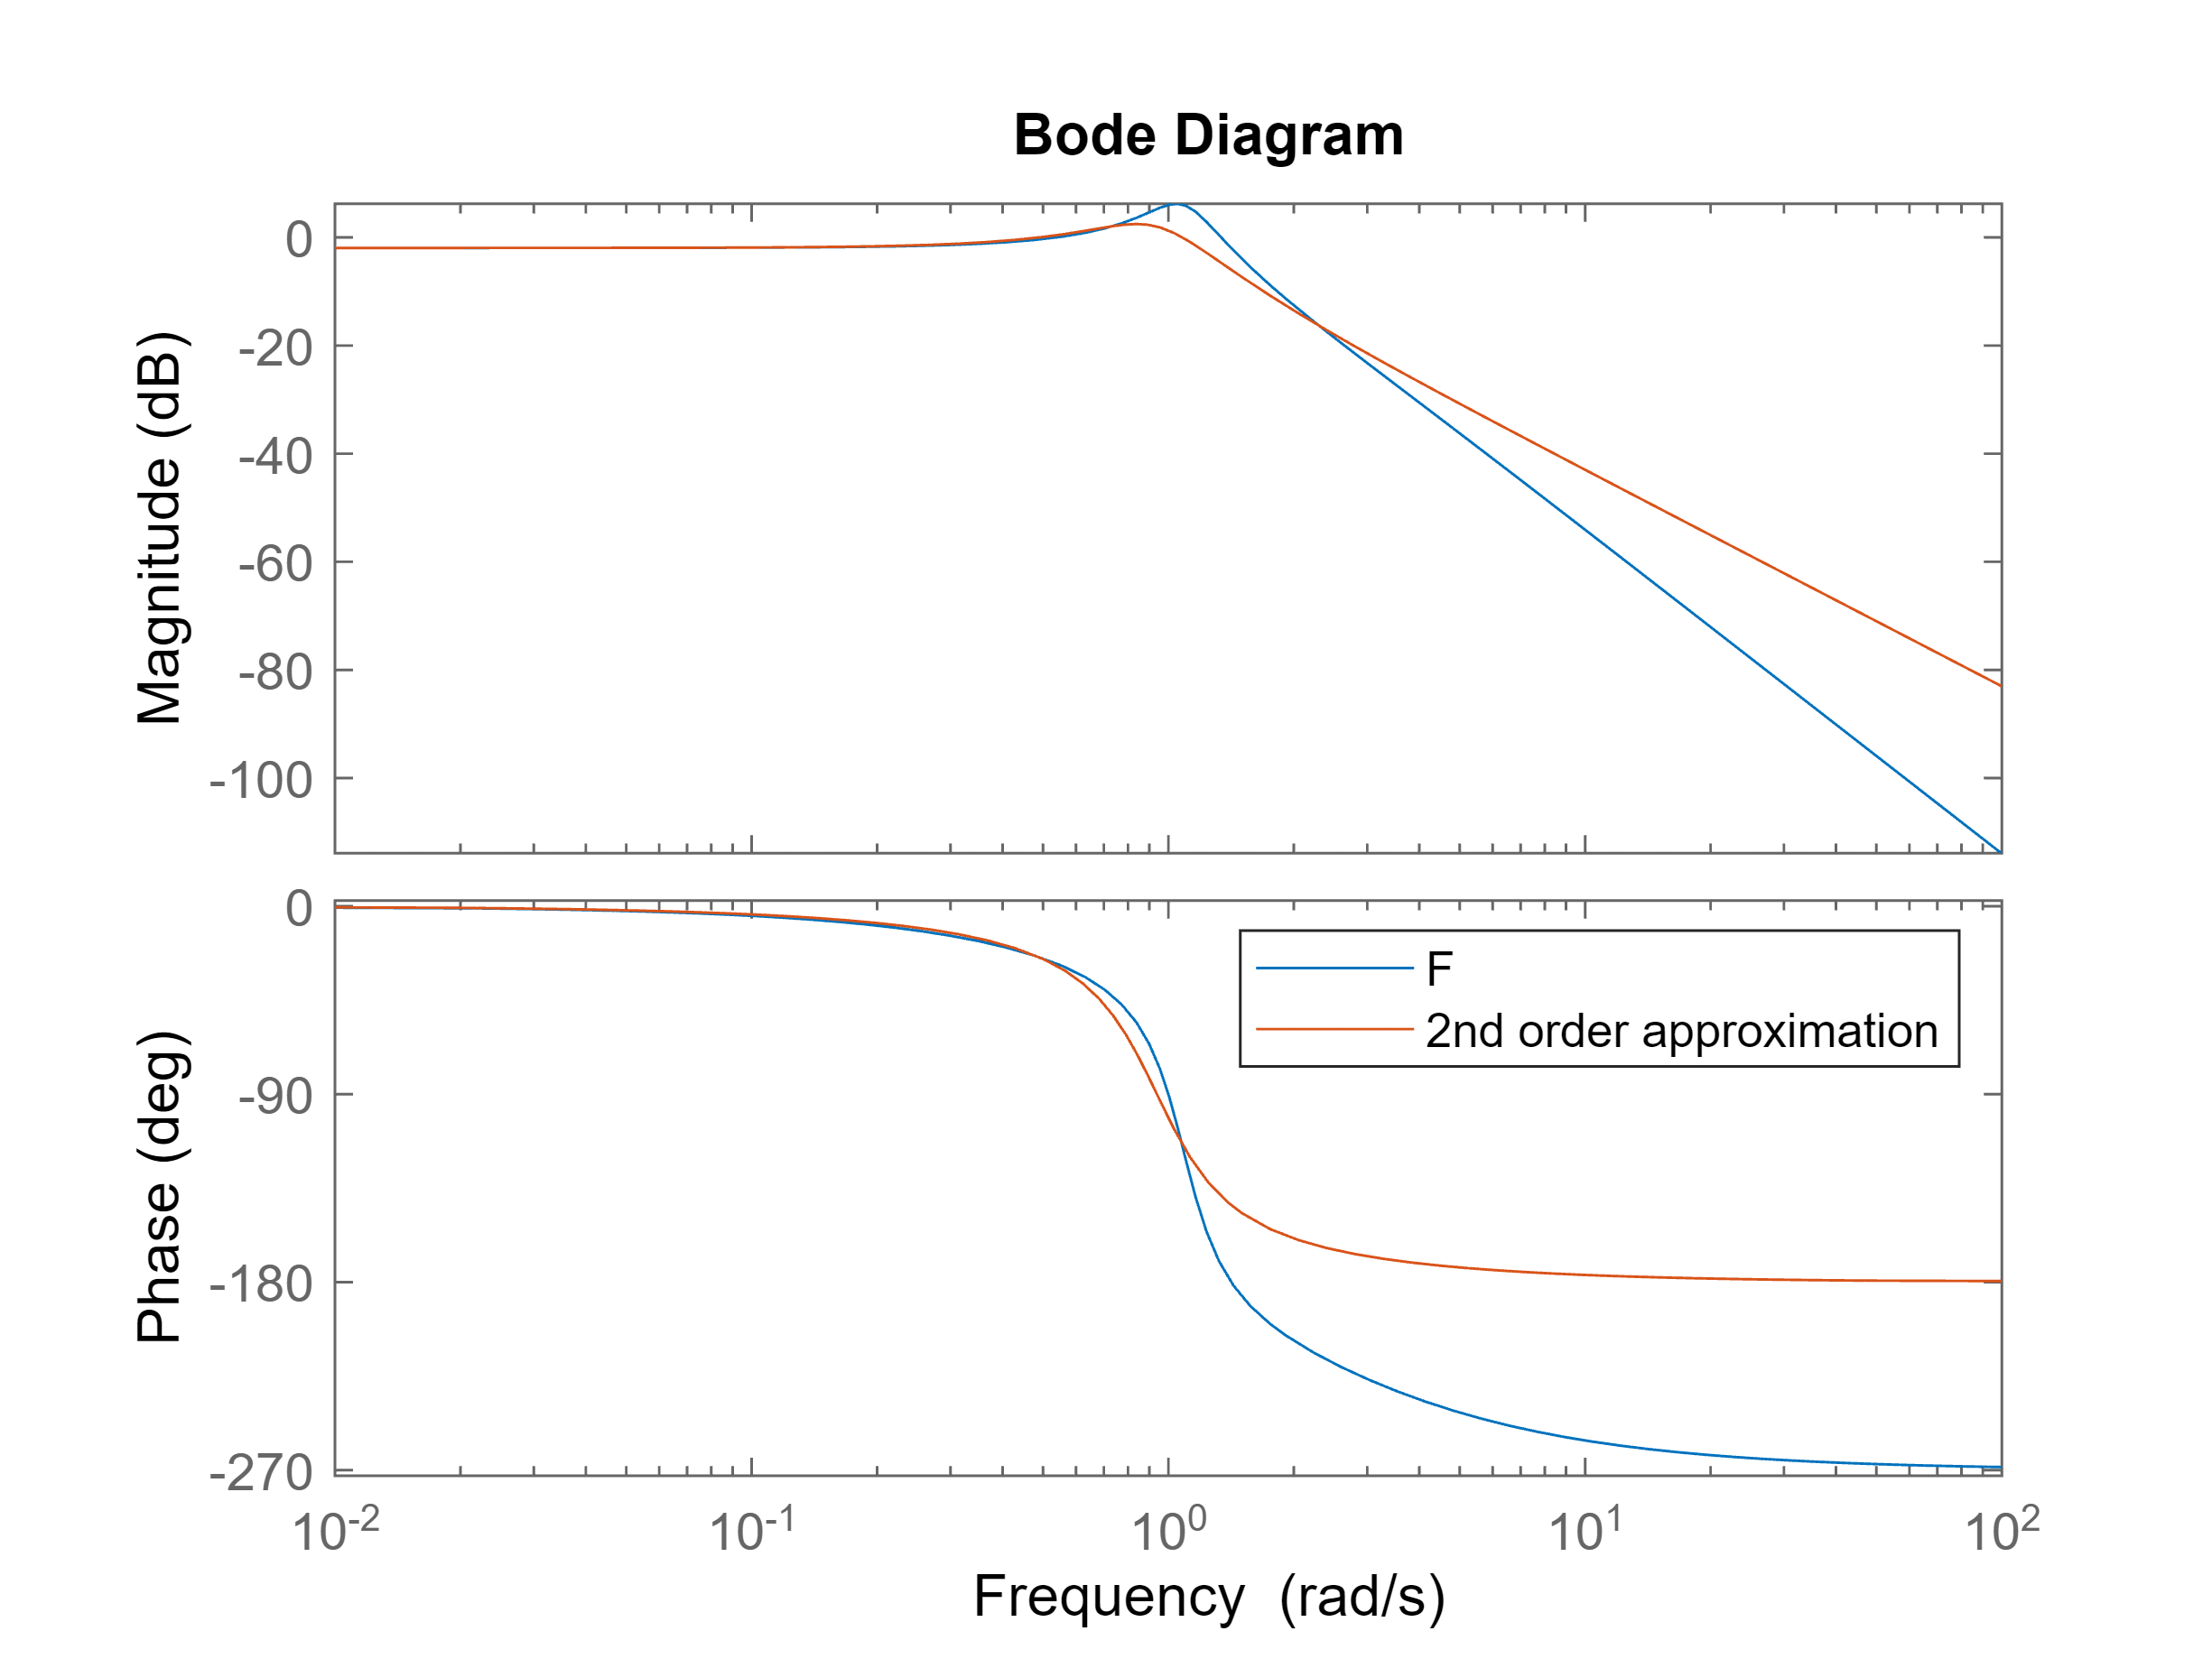

[GM,PM,wcg,wcp] = margin(L);

zeta = PM/100;
wn = wcp;

L0 = dcgain(L);

F_approx = 1/(1+2*zeta*s/wn + s^2/wn^2) *  (1 - 1/(1+L0));
F = feedback(L,1);

bode(F,F_approx)
legend('F','2nd order approximation')

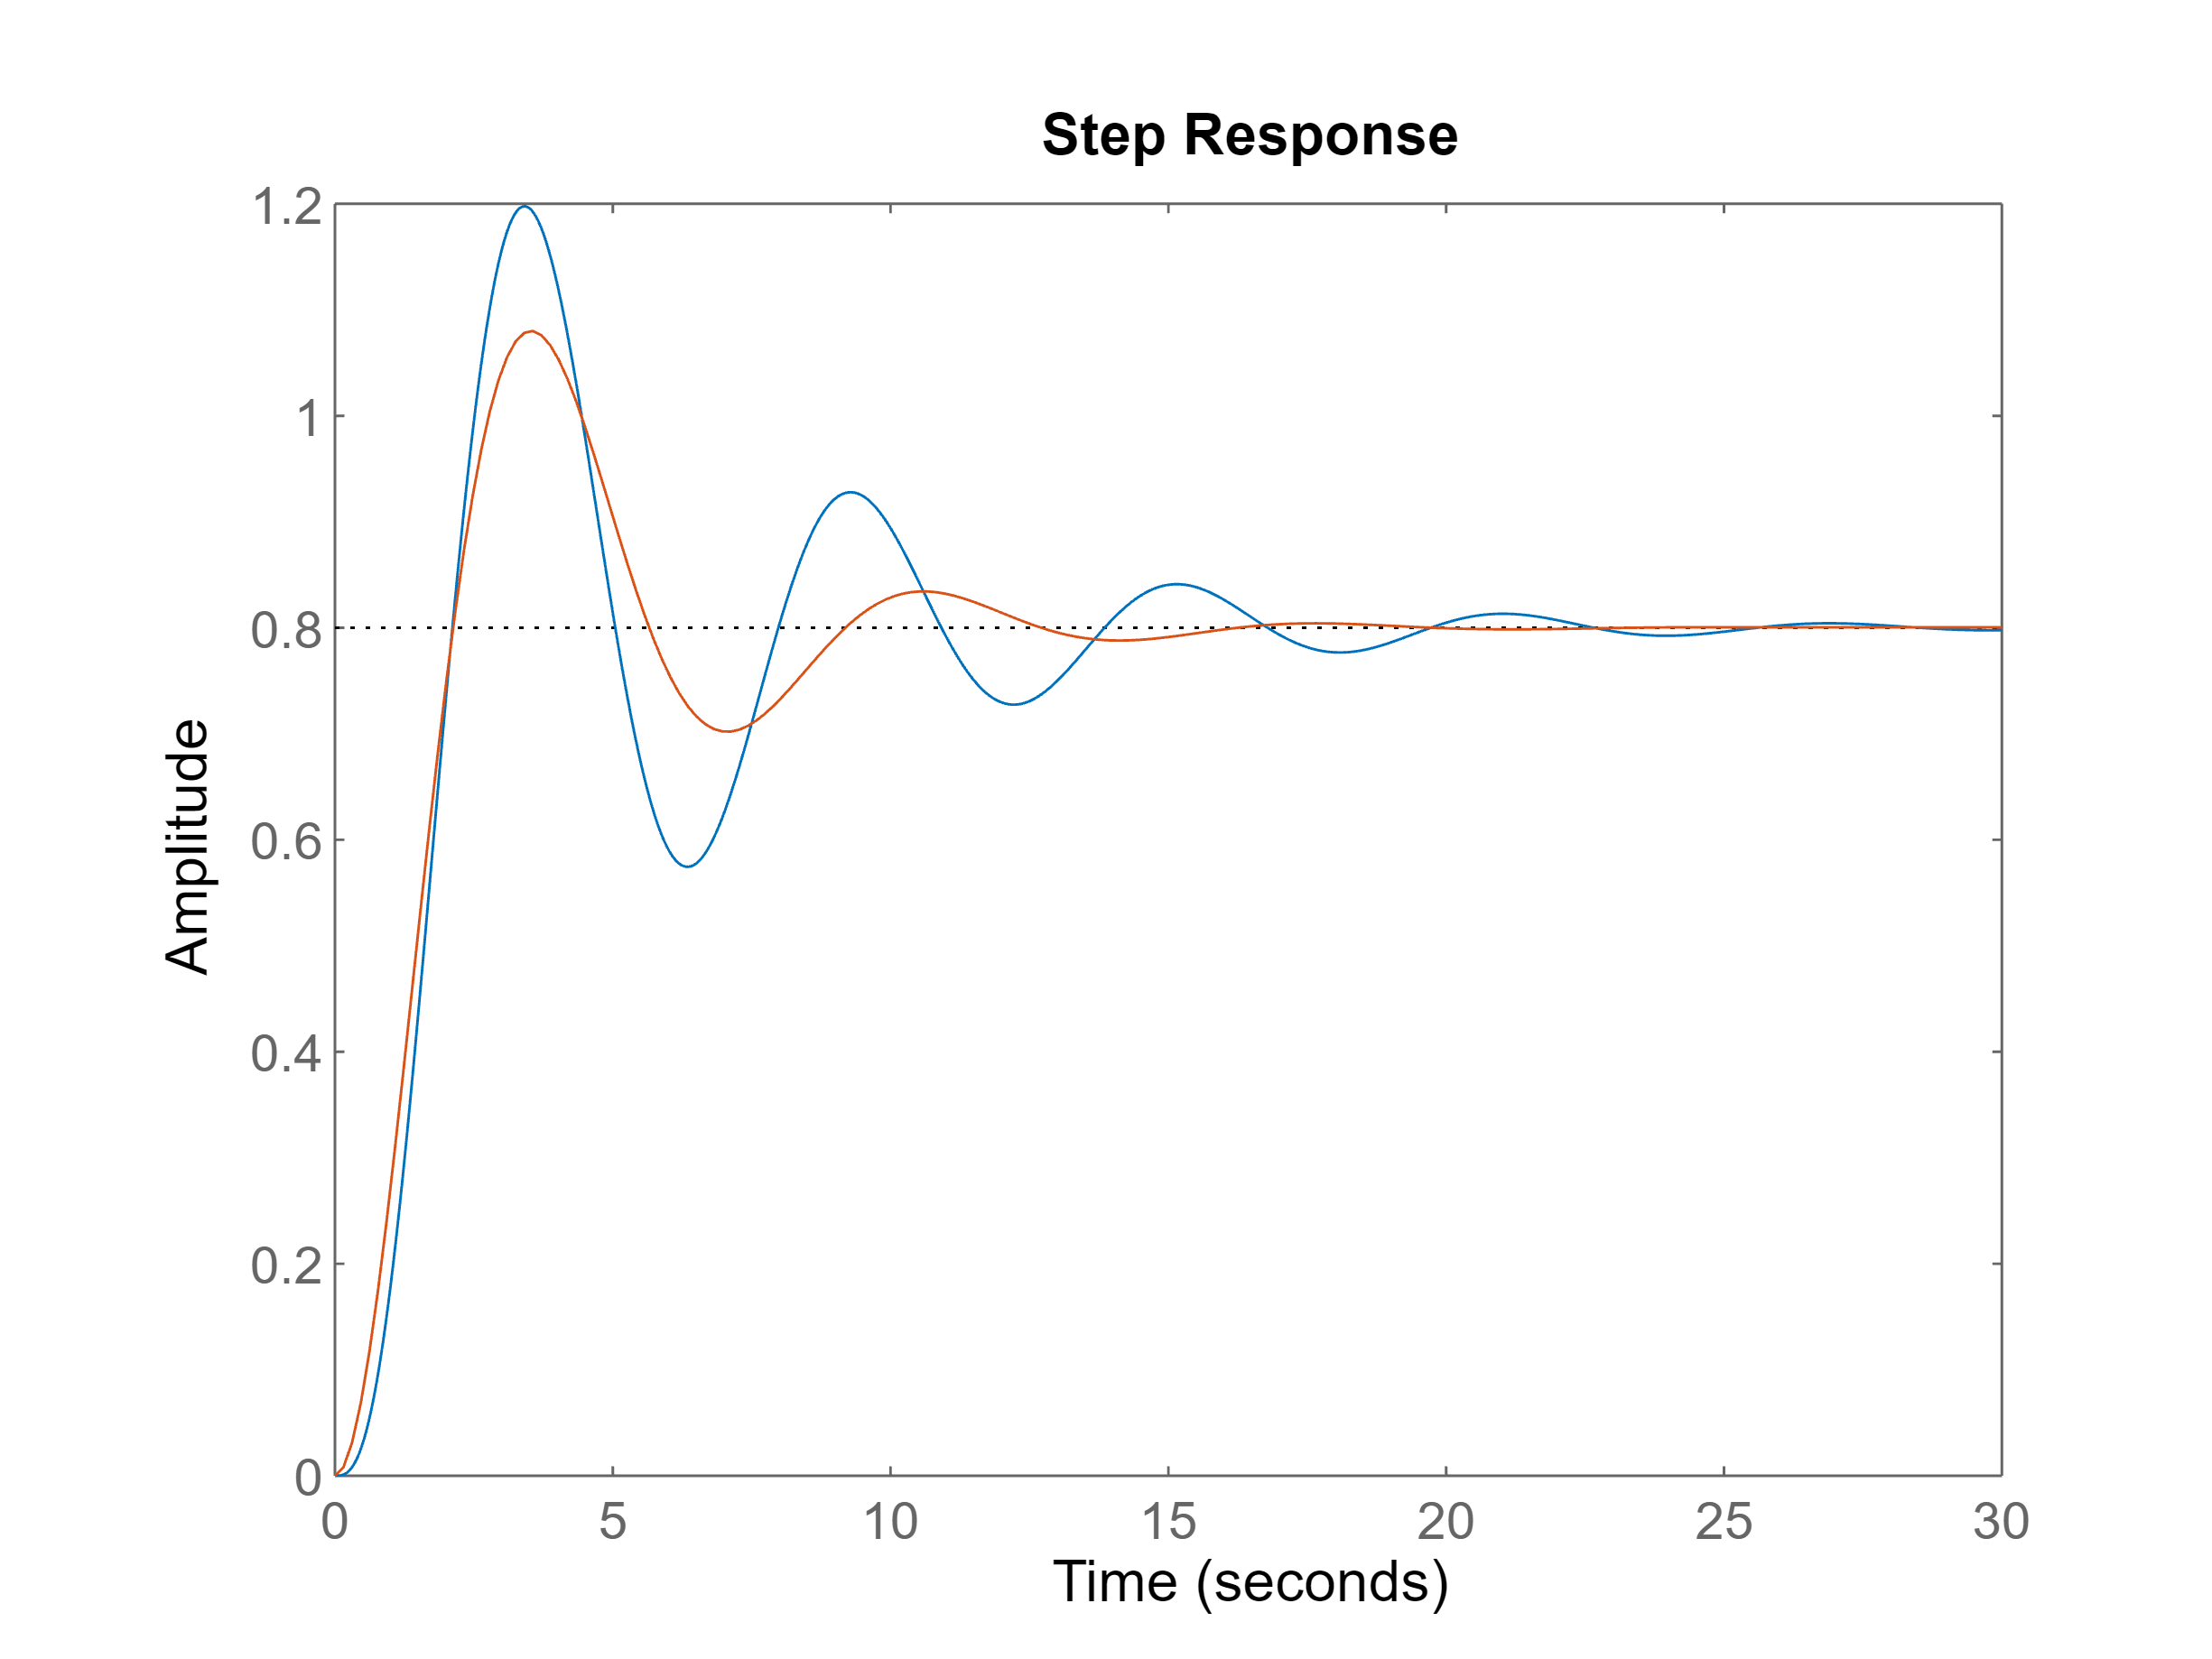

step(F,F_approx)

## Stabilità paradossale

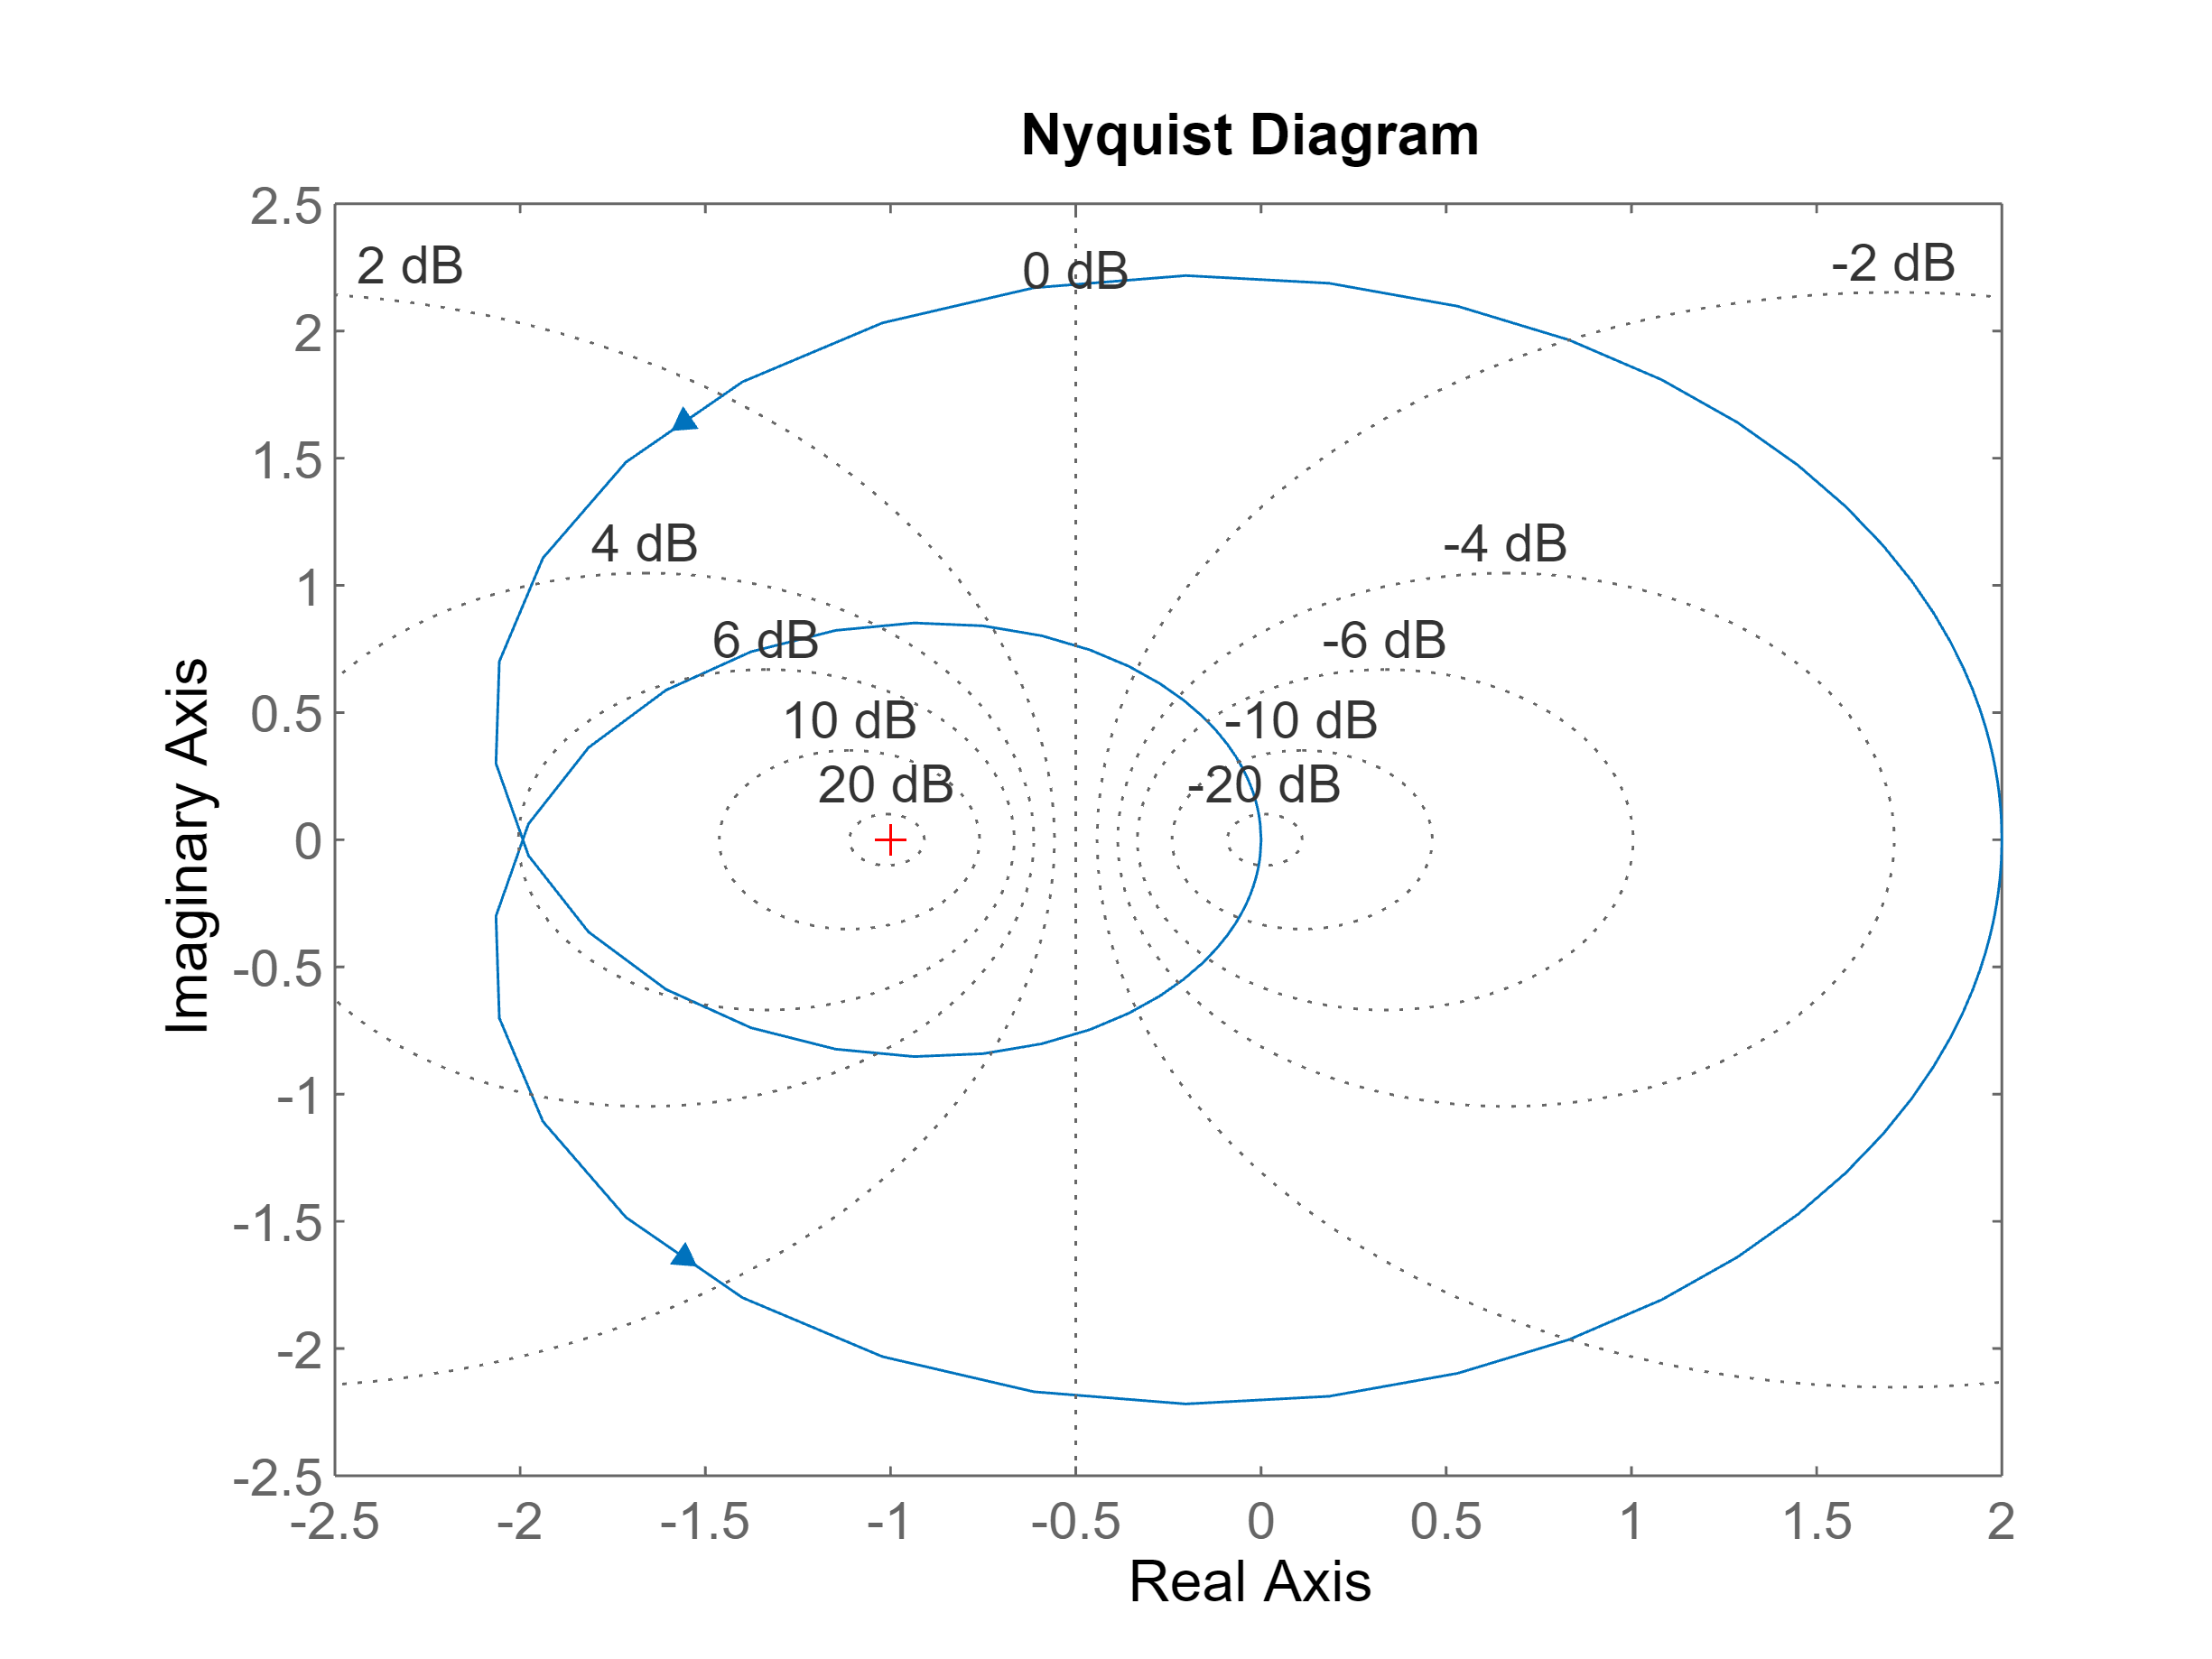

T1 = -1;
T2 = -2;
T0 = 3;

k = 2;

L = k*(1+s*T0)/((1+s*T1)*(1+s*T2));

figure
nyquist(L), grid on

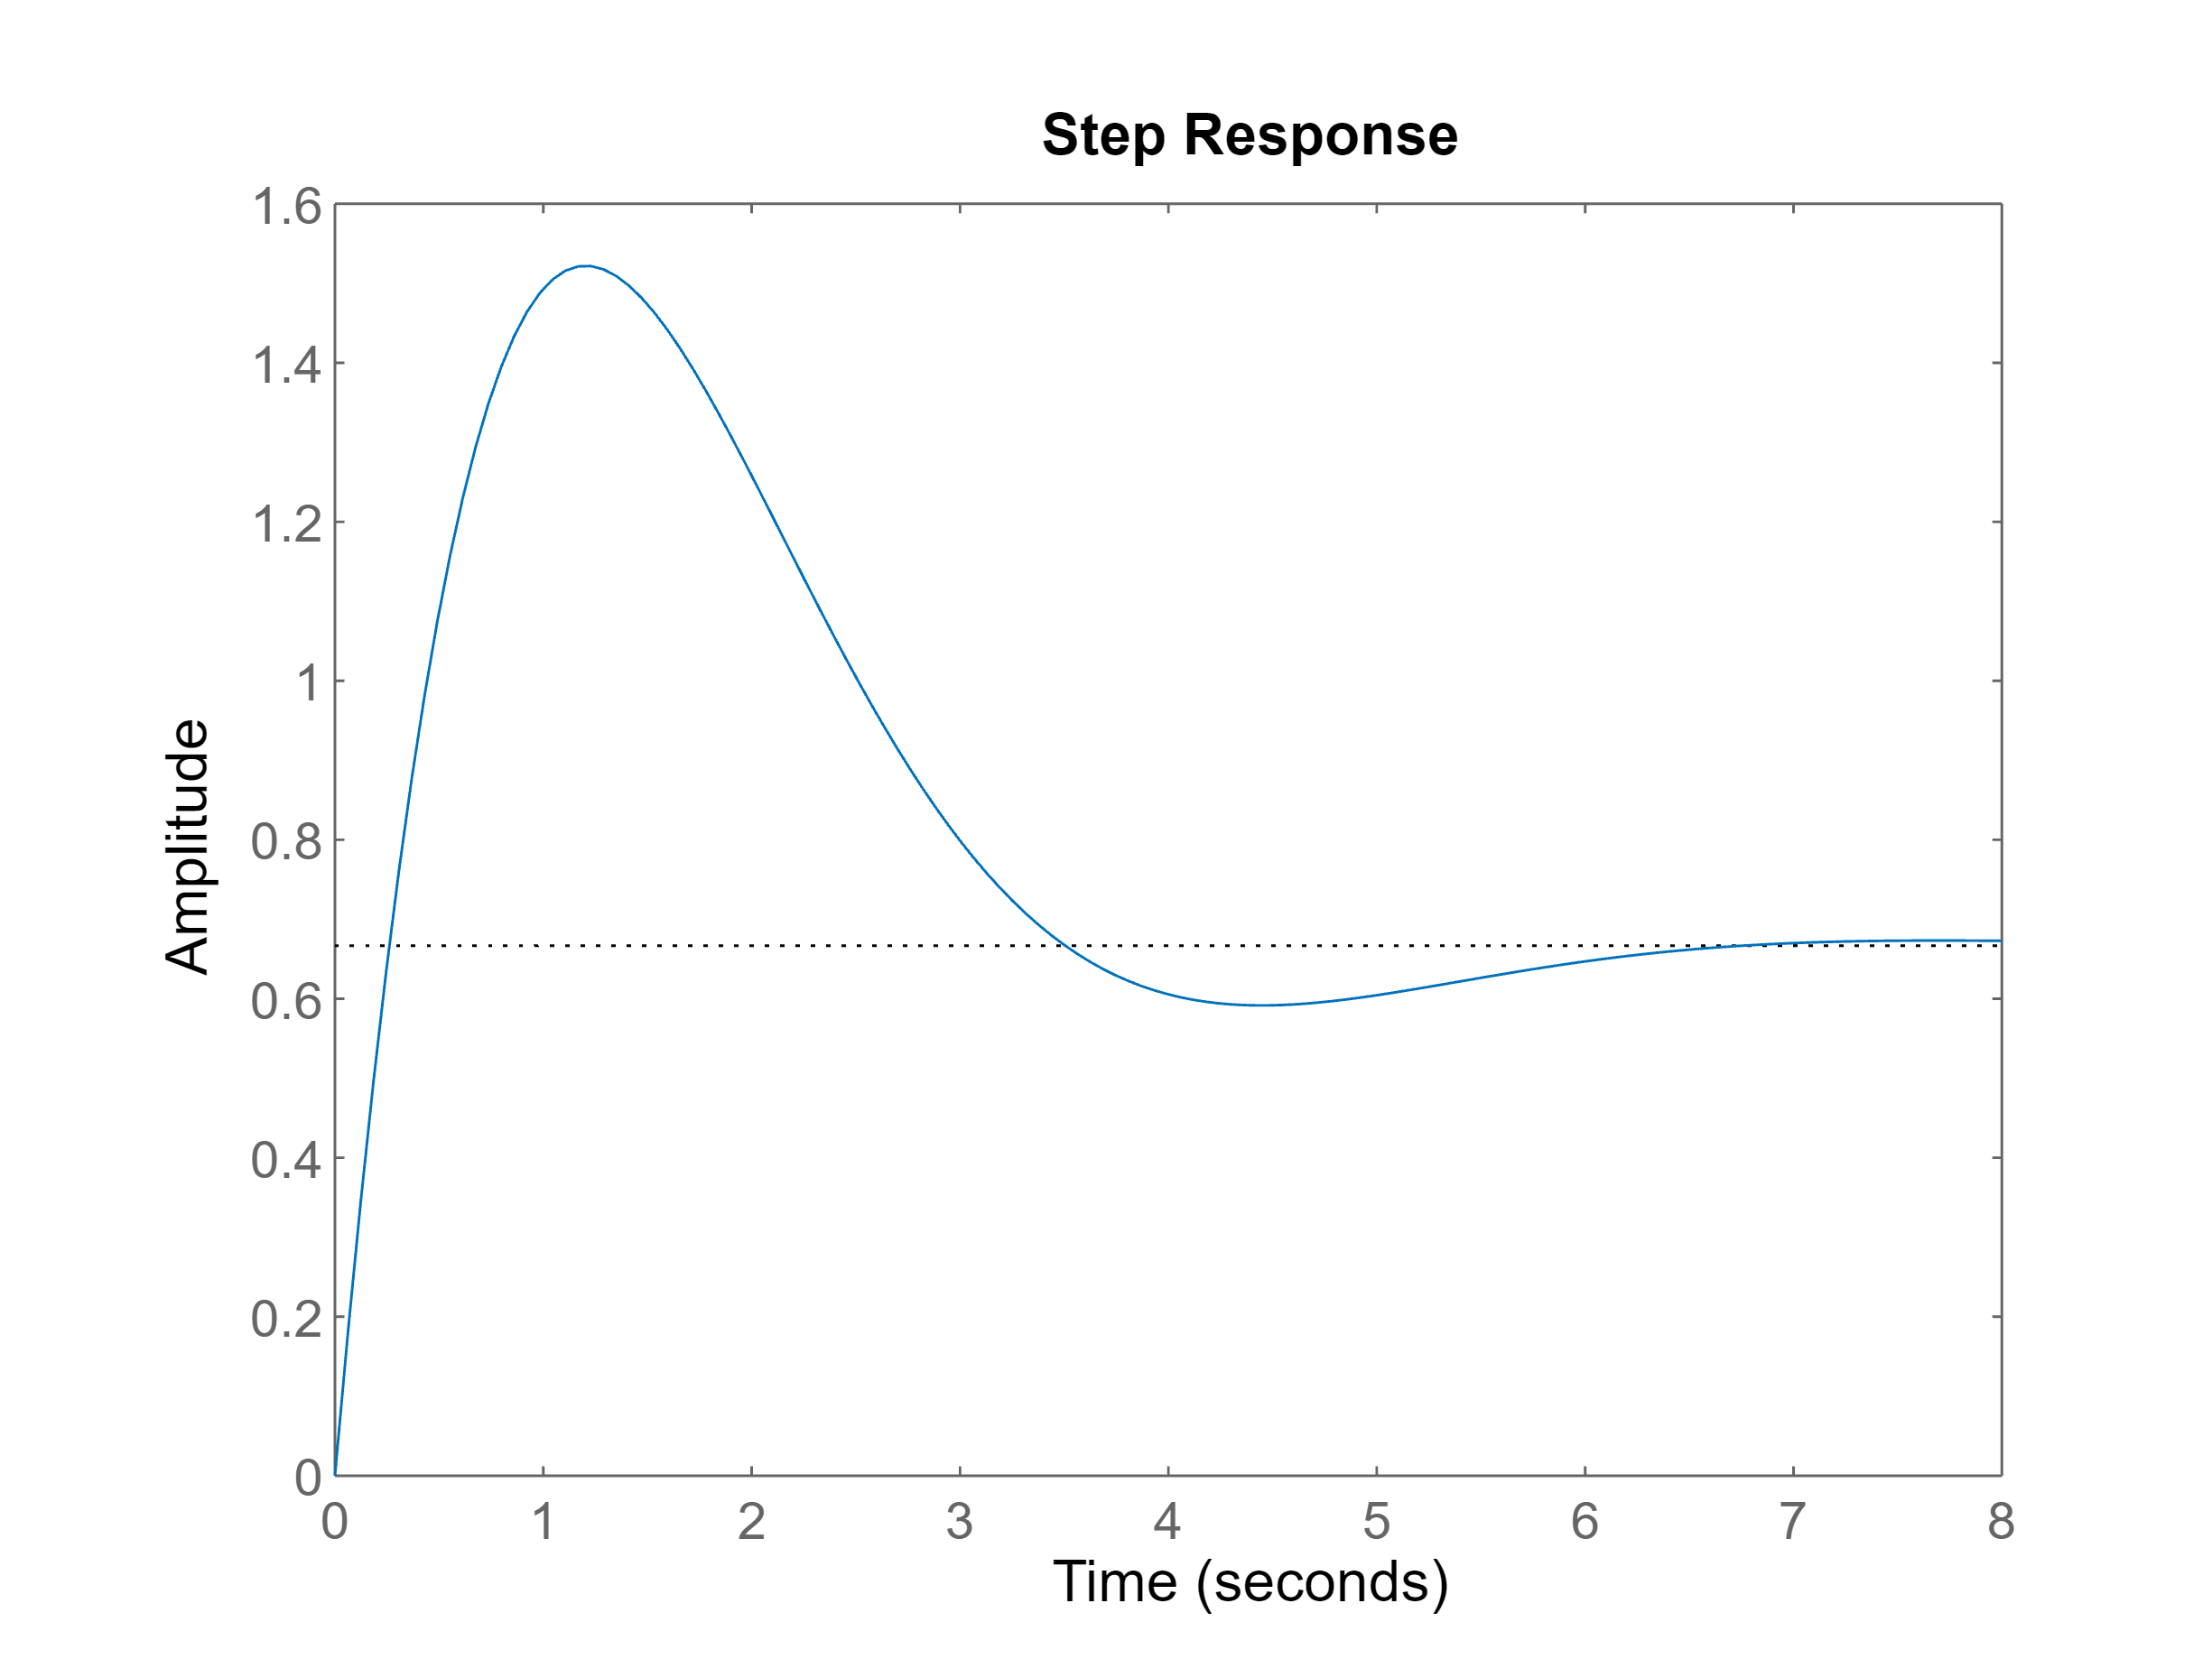

step(feedback(L,1))

## Stabilità condizionata

T01 = 0.3; 
T02 = 0.1;

T1 = 2;
T2 = 0.01;
T3 = 0.0003;

k = 100;

L = ((1+s*T01)*(1+s*T02)) / (s^2*(1+s*T1)*(1+s*T2))%*(1+s*T3));

L =
 
    0.03 s^2 + 0.4 s + 1
  -------------------------
  0.02 s^4 + 2.01 s^3 + s^2
 
Continuous-time transfer function.



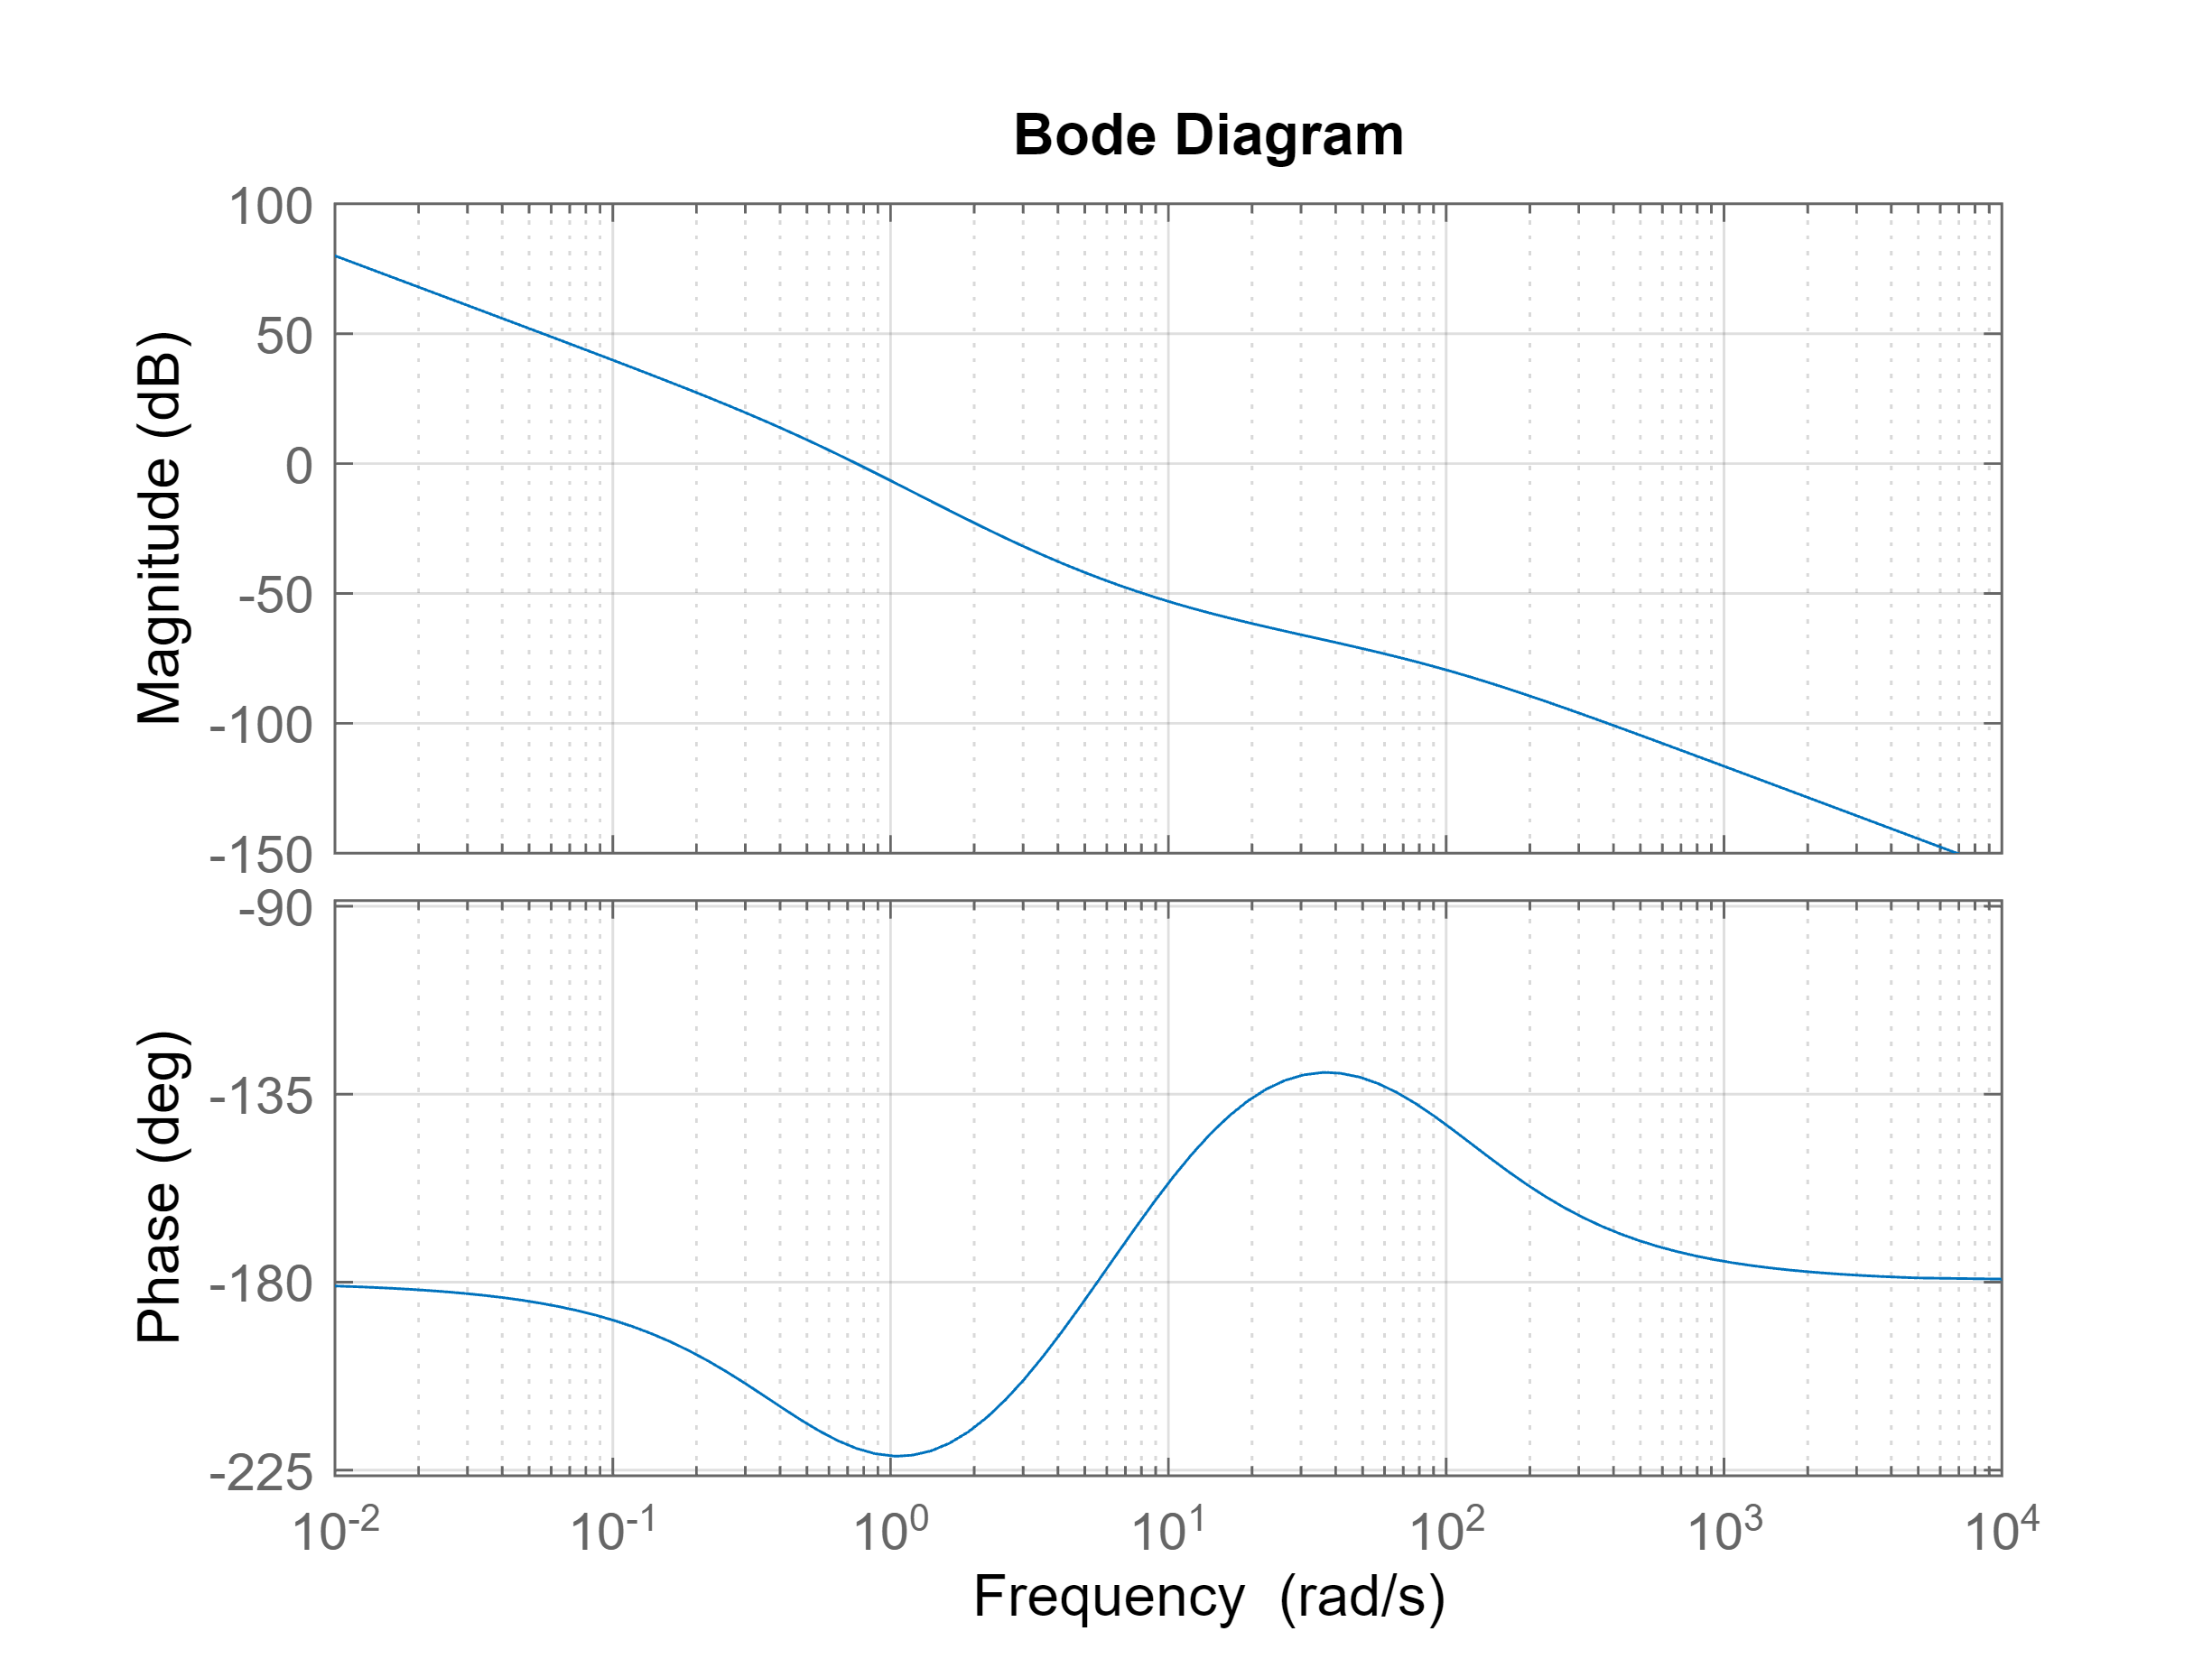

figure
bode(L), grid on

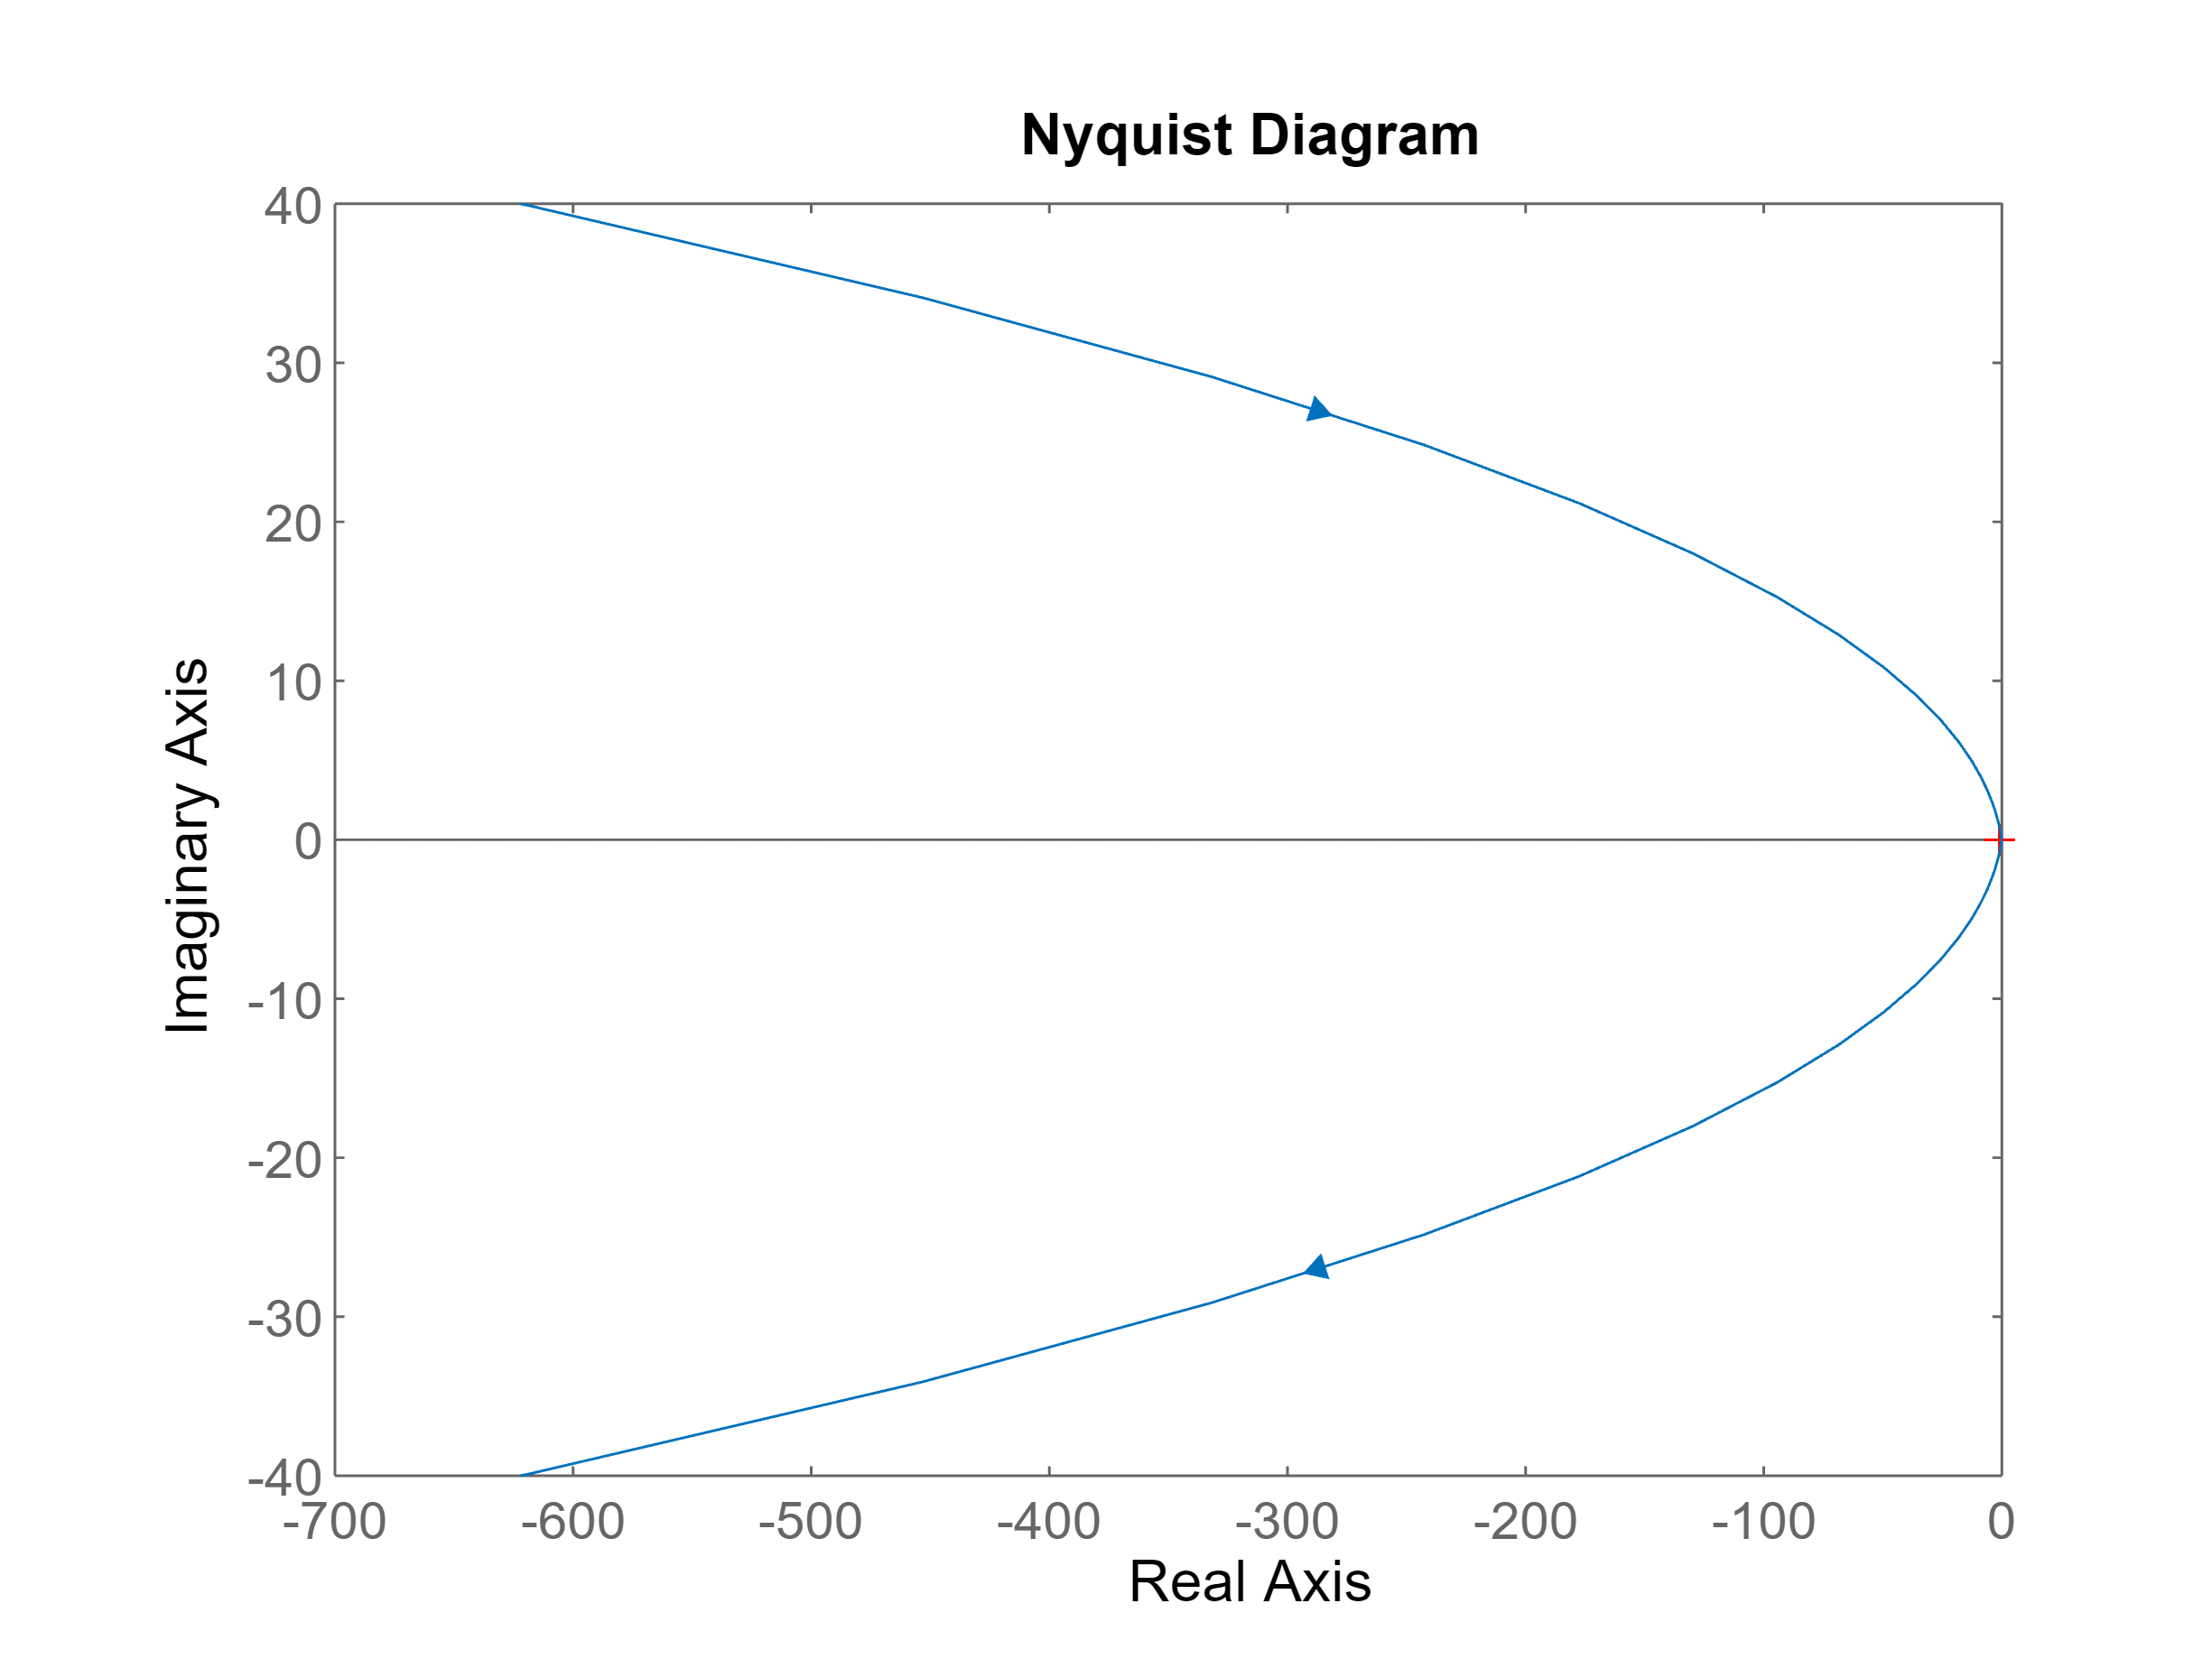

figure
nyquist(L)

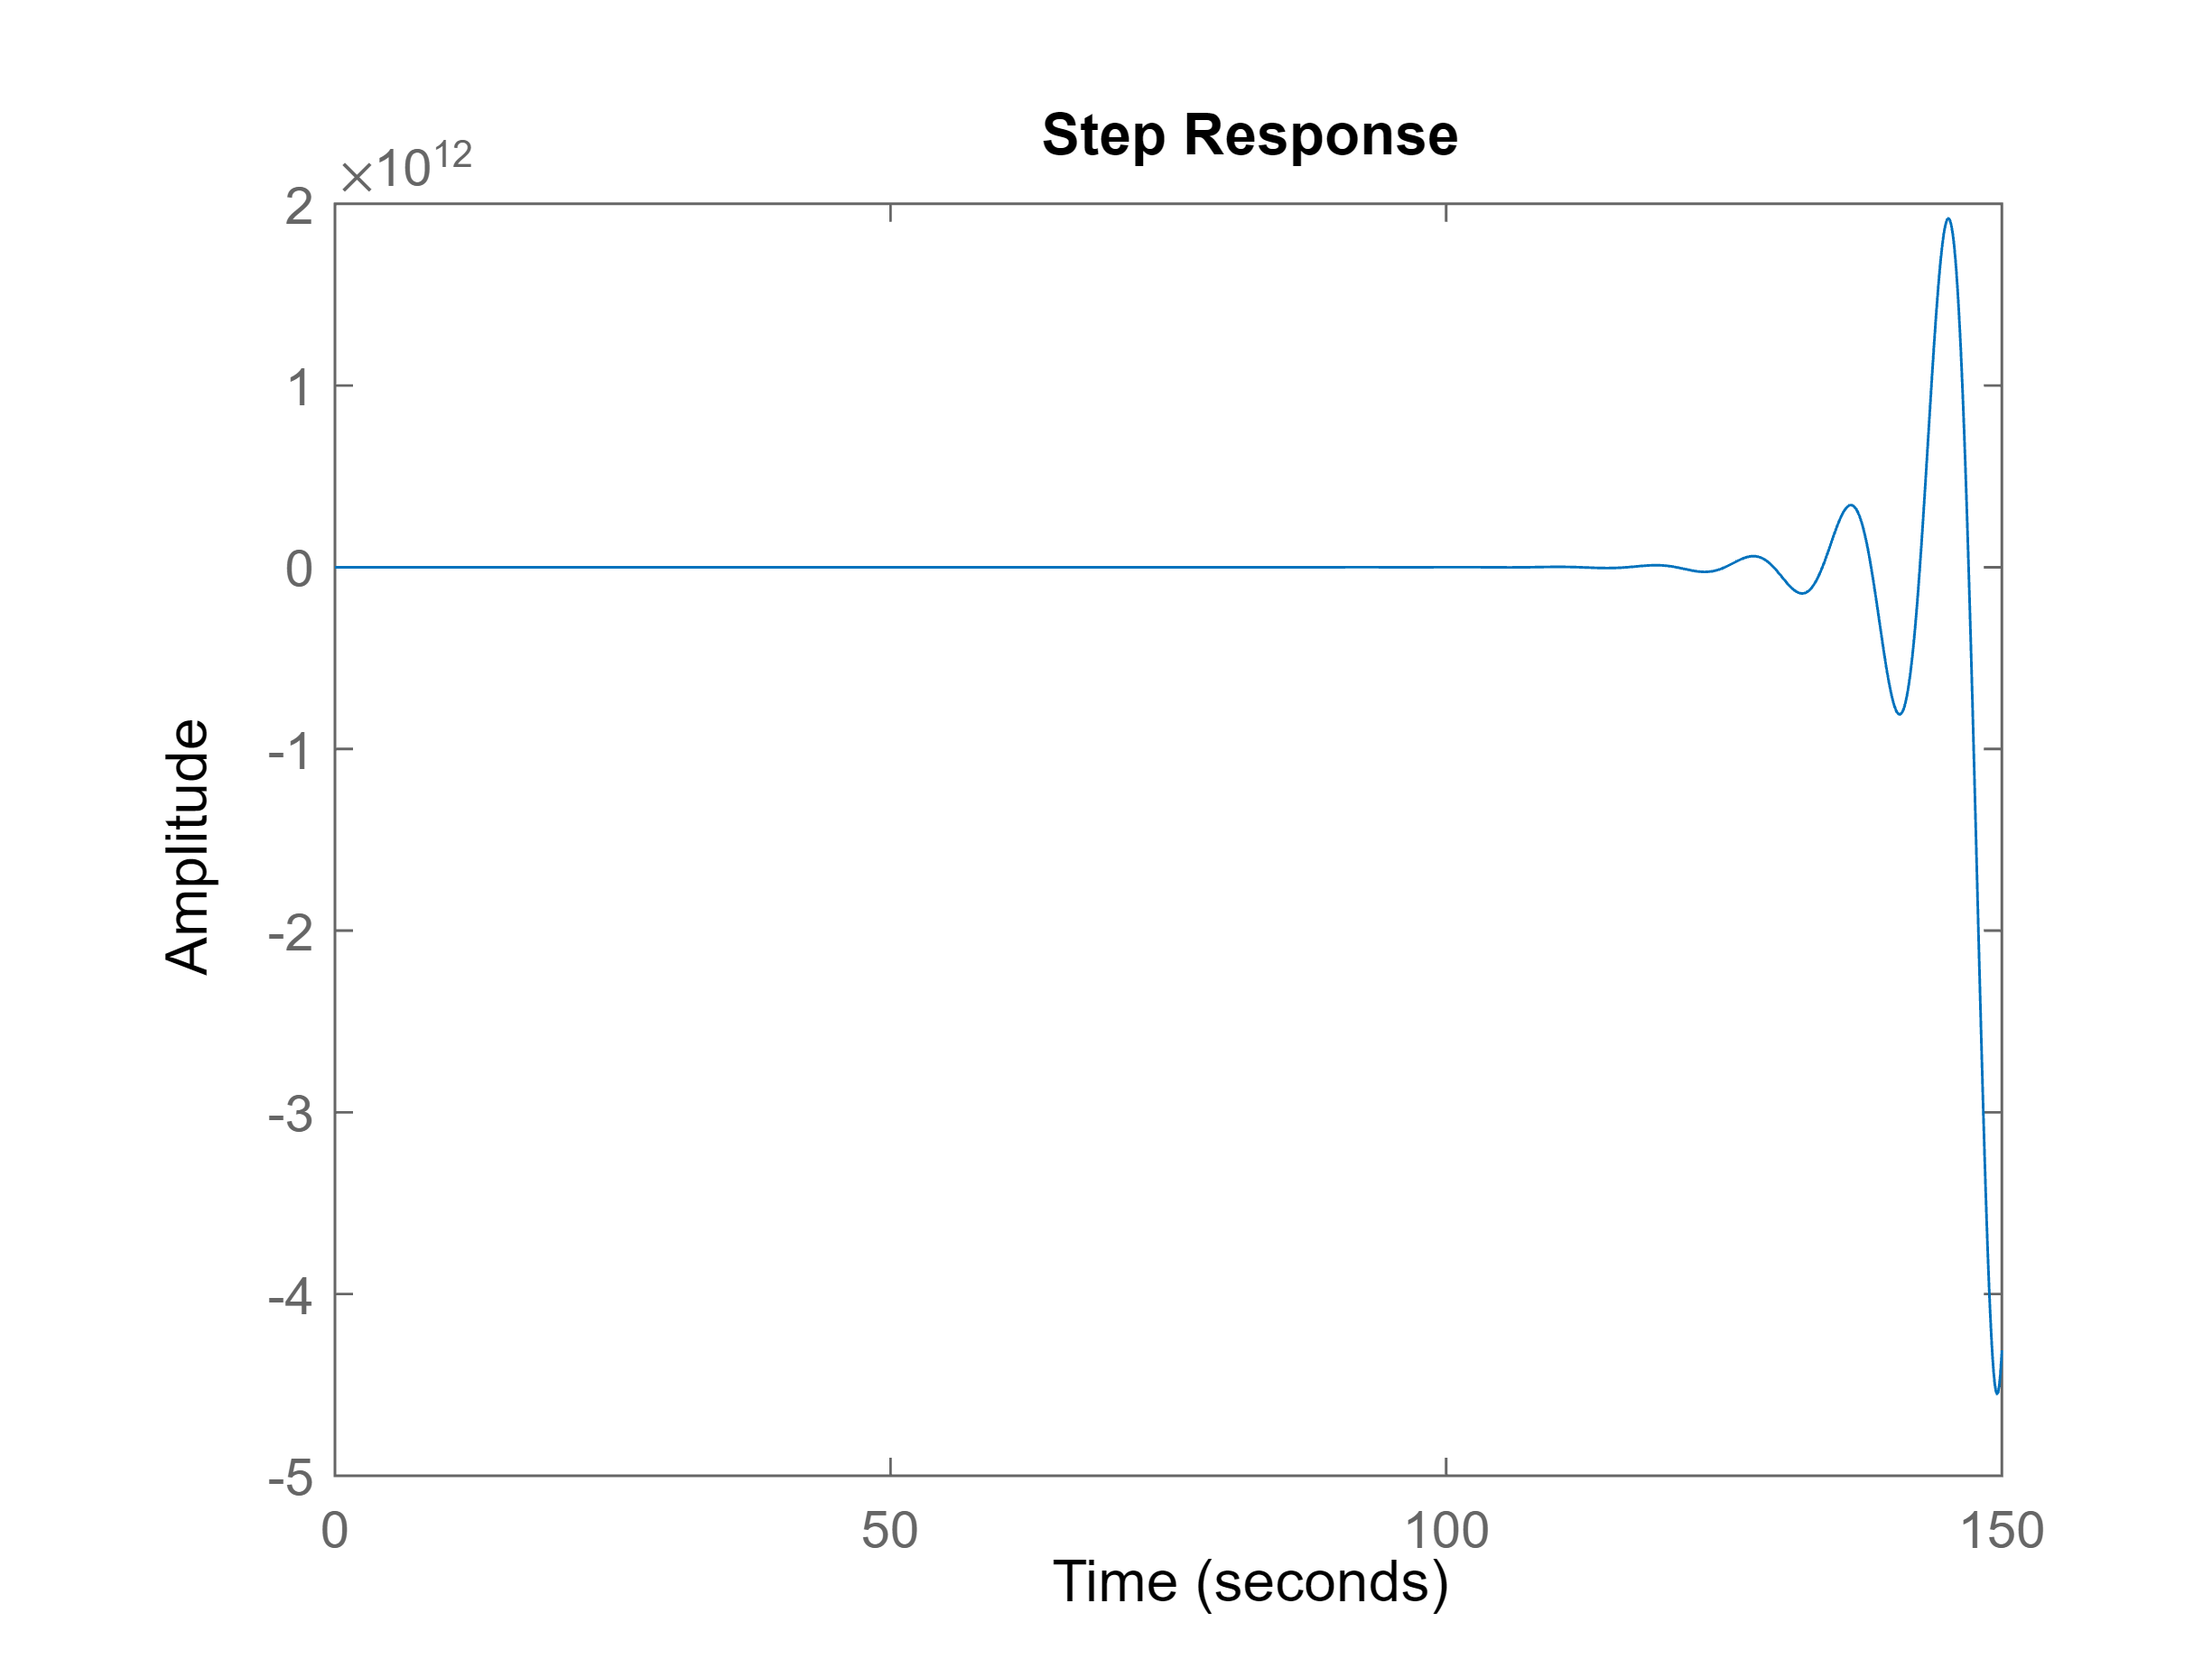

step(feedback(L,1))

## Instabilità intrinseca

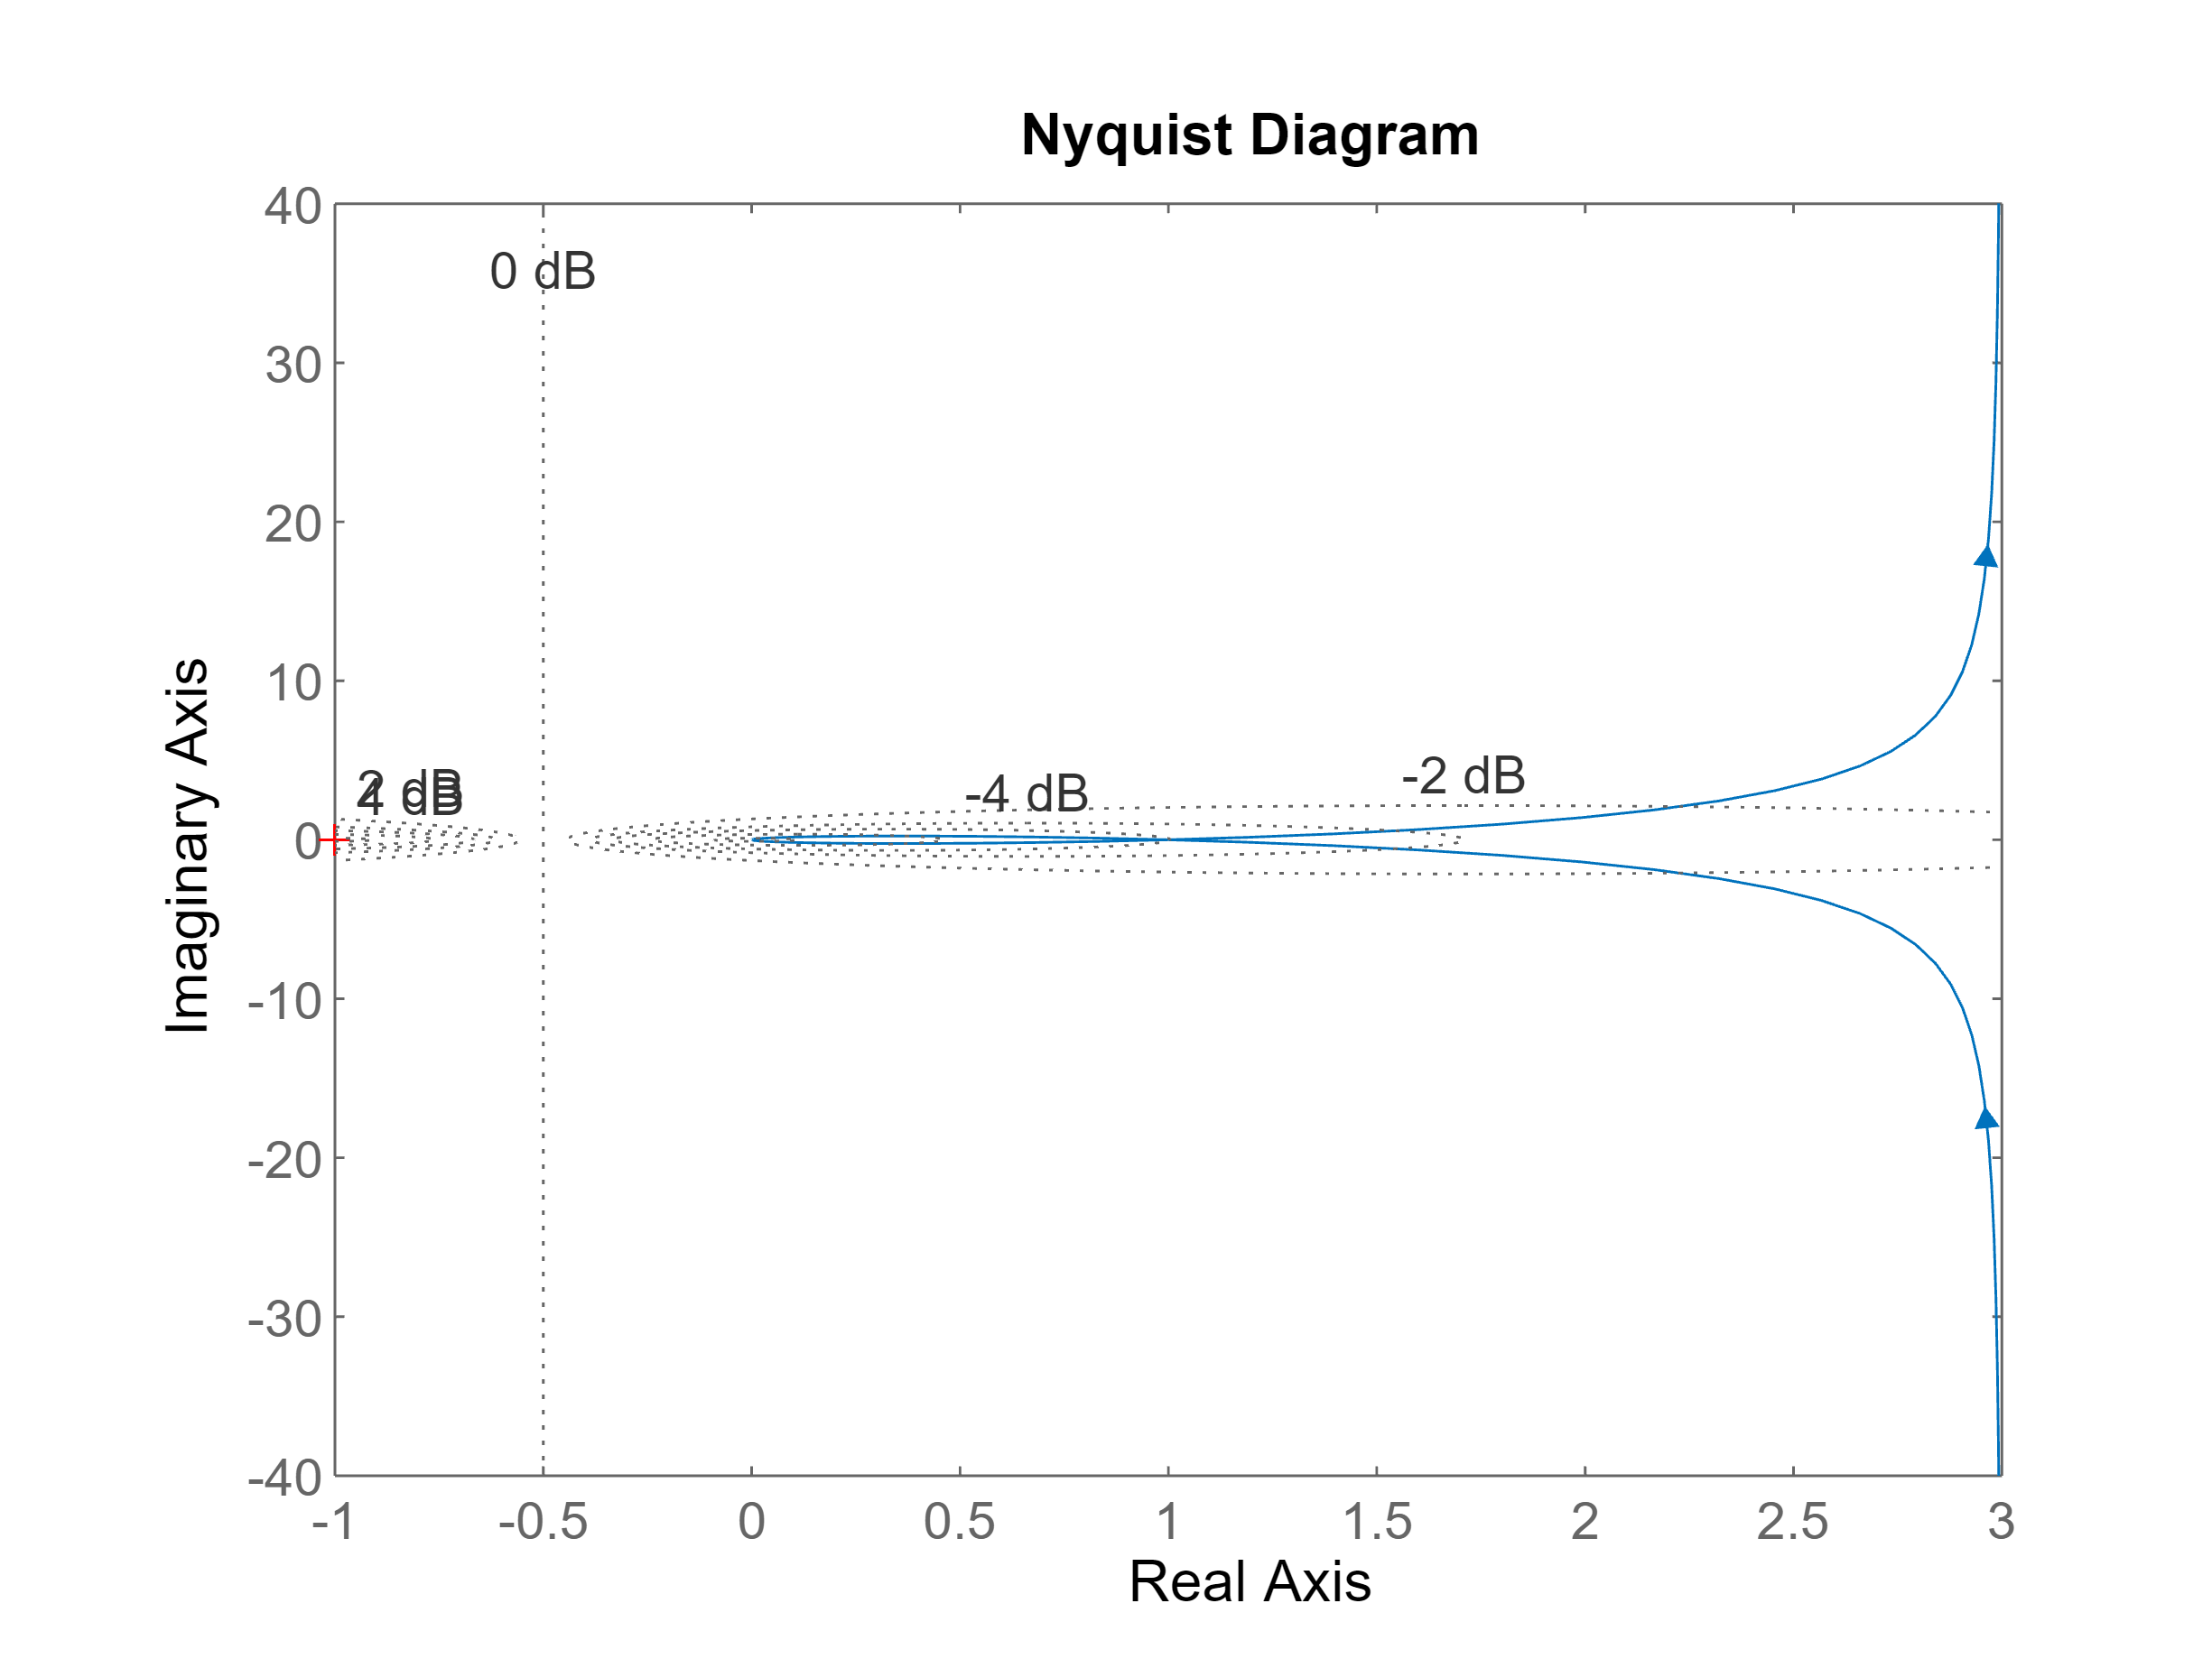

T0 = 1;
T1 = -2;

L = k*(1+s*T0)/(s*(1+s*T1));

figure
nyquist(L), grid on